# Lab 4 Data Analyis

Magnetometer calibration from going around in a circle around Ruggles rotary and then the Boston tour

clear
clc


Below is loading the data into the msg structures for the /imu and /gps topics from both the circling and tour parts of the data collection



circlingbag = rosbag('data_going_in_circles.bag');
tourbag = rosbag('data_driving.bag');

bSel_circling_imu = select(circlingbag,'Topic','/imu');
mstruct_circling_imu = readMessages(bSel_circling_imu,"DataFormat","struct");
bSel_circling_gps = select(circlingbag,'Topic','/gps');
mstruct_circling_gps = readMessages(bSel_circling_gps,"DataFormat","struct");


bSel_tour_imu = select(tourbag,'Topic','/imu');
mstruct_tour_imu = readMessages(bSel_tour_imu,"DataFormat","struct");
bSel_tour_gps = select(tourbag,'Topic','/gps');
mstruct_tour_gps = readMessages(bSel_tour_gps,"DataFormat","struct");


Now, we need to do the hard and soft iron calibrations. But this requires we plot the magnetometer X and Y data from the circling bag. This will be done below.

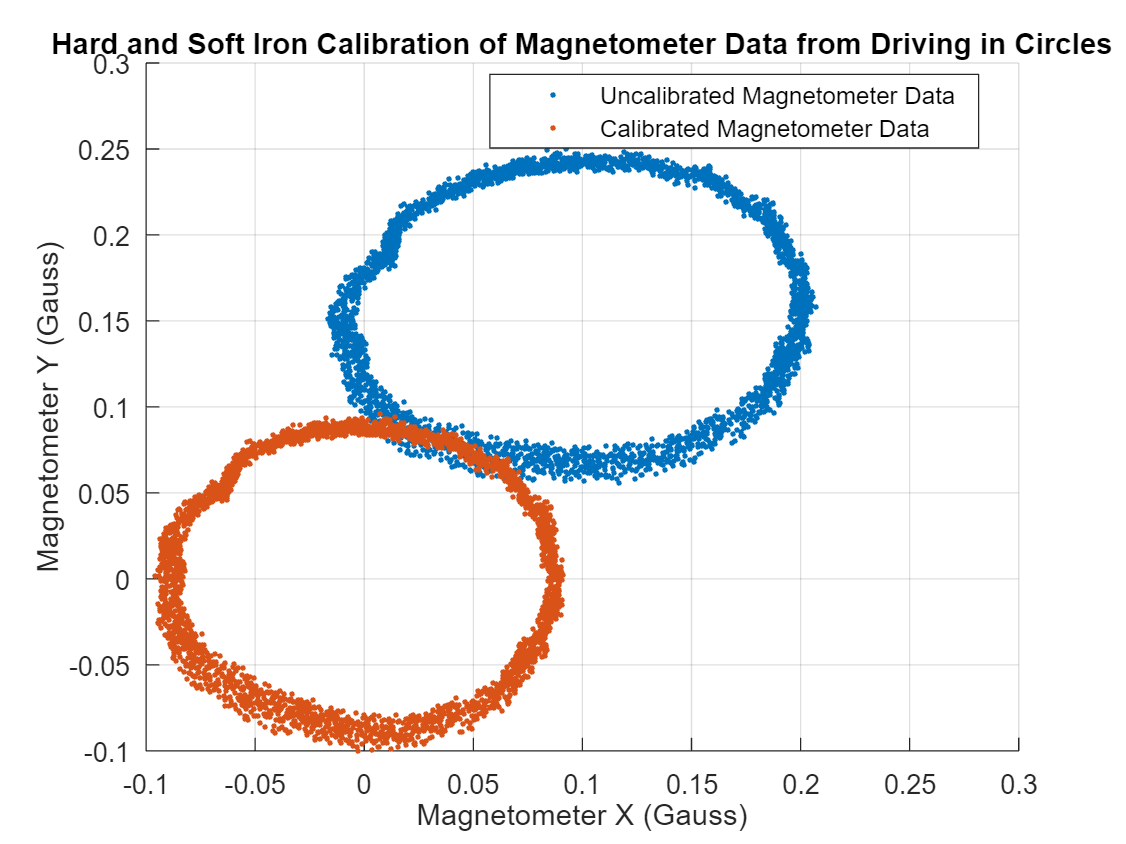


MagX_circling = double(cellfun(@(m) m.MagField.MagneticField_.X,mstruct_circling_imu)); % in teslas
MagX_circling = MagX_circling * 10^4; % converts to Gauss units
MagY_circling = double(cellfun(@(m) m.MagField.MagneticField_.Y,mstruct_circling_imu));
MagY_circling = MagY_circling * 10^4; % converts to Gauss units


scatter(MagX_circling(2000:length(MagX_circling)),MagY_circling(2000:length(MagY_circling)),'.');
grid on
title('Hard and Soft Iron Calibration of Magnetometer Data from Driving in Circles')
xlabel("Magnetometer X (Gauss)")
ylabel("Magnetometer Y (Gauss)")
xlim([-.1,0.3])
ylim([-.1,0.3])

MagX_circling_trim = MagX_circling(2000:length(MagX_circling));
MagY_circling_trim = MagY_circling(2000:length(MagY_circling));
ellipse_vals = fit_ellipse(MagX_circling_trim, MagY_circling_trim);
t = linspace(-.5*pi,1.5*pi, length(MagX_circling_trim));
a = ellipse_vals.a;
b = ellipse_vals.b;
short_axis = ellipse_vals.short_axis; 
long_axis = ellipse_vals.long_axis;
X0 = ellipse_vals.X0_in;
Y0 = ellipse_vals.Y0_in;
phi = ellipse_vals.phi;
x = X0 + a*cos(t);
x = x';
y = Y0 + b*sin(t);
y = y';
hold on



% accounting for translation (hard iron errors)
xt = MagX_circling_trim - X0;
yt = MagY_circling_trim - Y0;

% accounting for rotation (soft iron error)
alpha = phi;
R  = [cos(alpha) -sin(alpha); sin(alpha)  cos(alpha)];
rCoords = R*[xt' ; yt'];   
xr = rCoords(1,:)';      
yr = rCoords(2,:)';      
%plot(xr,yr,'.');

% fitting to circle/squishing (soft iron error)
squish_ratio = short_axis/long_axis;
xsquish = xr*squish_ratio;% squish x into circle shape
ysquish = yr; % no change

scatter(xsquish,ysquish,'.')
legend('Uncalibrated Magnetometer Data', 'Calibrated Magnetometer Data')
hold off

legend("Position", [0.43492,0.82473,0.43429,0.087563])

~THIS~ concludes the calibration portion of the lab. Let's continue......

NOW (with correction) we'll just be working with the tour data. We'll have the raw data and then we'll use our calibrations from the previous section to calibrate our tour data. 

First, need to grab time for driving

time_secs = double(cellfun(@(m) m.Header.Stamp.Sec,mstruct_tour_imu));
time_nsecs = double(cellfun(@(m) double(m.Header.Stamp.Nsec),mstruct_tour_imu));

time = time_secs + (time_nsecs * 10^-9);
time = time - time(1);

From this, we can calculate the heading (yaw angle) (and there are various methods of calculations they want us to make to create the comparison). I believe we're graphing these against time.

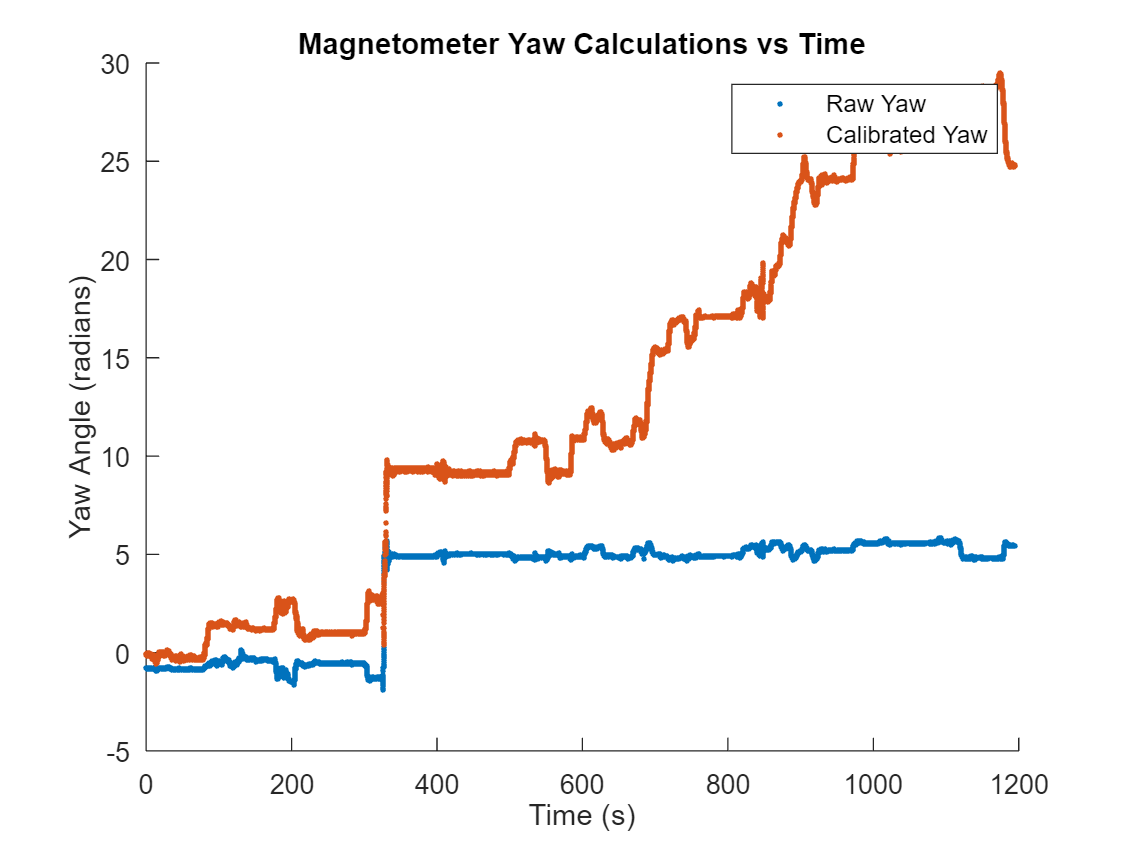

% so yaw = atan2(-magy,magx). We'll use the corrected and raw values for
% driving and then plot these 





MagX_tour = double(cellfun(@(m) m.MagField.MagneticField_.X,mstruct_tour_imu)) * 10^4; % multiply by 10^4 to get Gauss
MagY_tour = double(cellfun(@(m) m.MagField.MagneticField_.Y,mstruct_tour_imu)) * 10^4; % multiply by 10^4 to get Gauss

MagX_tour = unwrap(MagX_tour);
MagY_tour = unwrap(MagY_tour);


%%%%% RAW YAW CALC
yaw_raw = atan2(-MagY_tour,MagX_tour);

%%%%% CALIBRATED YAW CALC
% now apply corrections...

% first, translate
xt_tour = MagX_tour - X0;
yt_tour = MagY_tour - Y0;

% then, rotate
alpha = phi;
R  = [cos(alpha) -sin(alpha); sin(alpha)  cos(alpha)];
rCoords = R*[xt_tour' ; yt_tour'];   
xr_tour = rCoords(1,:)';      
yr_tour = rCoords(2,:)'; 

% then squish to circle
xsquish_tour = xr_tour*squish_ratio;
ysquish_tour = yr_tour;




xsquish_unwrapped_tour = wrapToPi(xsquish_tour);
ysquish_unwrapped_tour = wrapToPi(ysquish_tour);
yaw_corrected = atan2(-ysquish_unwrapped_tour, xsquish_unwrapped_tour);




scatter(time,unwrap(yaw_raw),'.'); % raw yaw
title('Magnetometer Yaw Calculations vs Time');
xlabel("Time (s)");
ylabel("Yaw Angle (radians)");
hold on
scatter(time,unwrap(yaw_corrected),'.'); % yaw from magnetometer, corrected
legend("Raw Yaw","Calibrated Yaw");

hold off

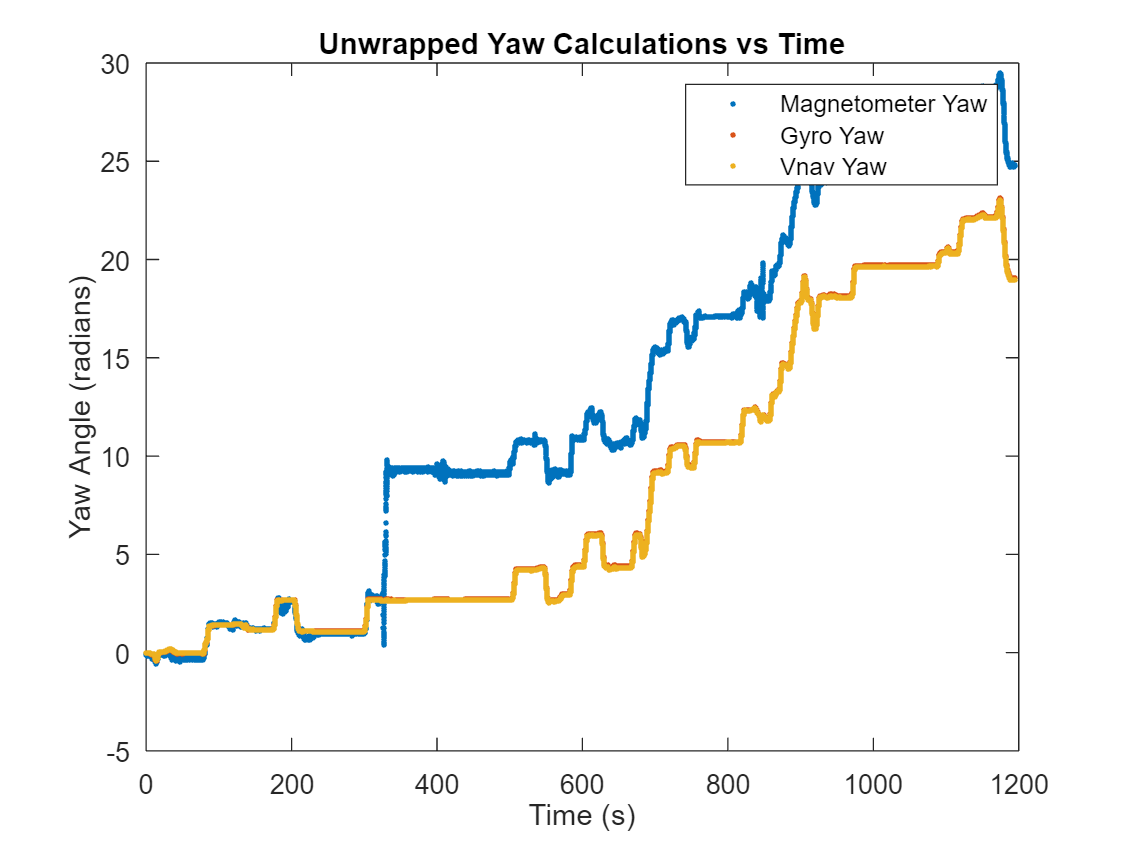



wrappingMagYaw_corrected = wrapToPi(yaw_corrected);
unwrapped_mag_yaw_corrected = unwrap(wrappingMagYaw_corrected);
plot(time,unwrapped_mag_yaw_corrected,'.')
title('Unwrapped Yaw Calculations vs Time');% post wrap and unwrapping
xlabel('Time (s)')
ylabel('Yaw Angle (radians)')

hold on


% OKAY, that was the corrected magnetometer calculation of yaw angle (then plotted against the raw). NOW, we'll find YAW ANGLE again, but by USING THE GYROSCOPE. Use recorded angular velocity of z (aka yaw rate), itegrate w/ respect to time, replot against time. Handout contains potentially useful functions.
% hold off
% first, read in gyro z data

yawrate_gyro = double(cellfun(@(m) m.Imu.AngularVelocity.Z,mstruct_tour_imu)); % units: rad/s


yaw_gyro = cumtrapz(time, yawrate_gyro);

scatter(time,yaw_gyro,'.');
wrapped_gyro_yaw = wrapToPi(yaw_gyro);
%title("Unwrapped Gyroscopic Yaw vs Time")
%xlabel('Time (s)')
%ylabel('Gyroscopic Yaw Angle (radians)')

%plot(time,wrapped_gyro_yaw,'.');
%title("Wrapped Gyroscopic Yaw vs Time")

% that finishes gyroscope yaw calculation, let's move on....

 


% getting quaternion positions first (w,x,y,z)
quatpositions= zeros(length(time),4);

quatpositions(:,1) = double(cellfun(@(m) m.Imu.Orientation.W,mstruct_tour_imu)); % w of quaternion
quatpositions(:,2) = double(cellfun(@(m) m.Imu.Orientation.X,mstruct_tour_imu)); % x of quaternion
quatpositions(:,3) = double(cellfun(@(m) m.Imu.Orientation.Y,mstruct_tour_imu)); % y of quaternion
quatpositions(:,4) = double(cellfun(@(m) m.Imu.Orientation.Z,mstruct_tour_imu)); % z of quaternion

% getting euler angles from quaternion (again, format of quatpositions is
% W,X,Y,Z. Format of eulerpositions after quat2eul is z,y,x but I'm going
% to switch the columns so the eulerpositions format is *Actually* X,Y,Z
% UNIT OF euler angles is radians

eulerpositions = quat2eul(quatpositions);
% switching the columns
dummyColumn = eulerpositions(:,1);
eulerpositions(:,1) = eulerpositions(:,3);
eulerpositions(:,3) = dummyColumn;
Vnav_yaw_wrapped = wrapToPi(eulerpositions(:,3));
Vnav_yaw_unwrapped = unwrap(Vnav_yaw_wrapped);
Vnav_yaw_unwrapped = Vnav_yaw_unwrapped - Vnav_yaw_unwrapped(1);
plot(time, Vnav_yaw_unwrapped, '.');
%title("Unwrapped Vectornav Yaw");

legend('Magnetometer Yaw','Gyro Yaw','Vnav Yaw')

hold off

%plot(time, eulerpositions(:,3)); % plot of the yaw from vectornav
%title("Vectornav Yaw");



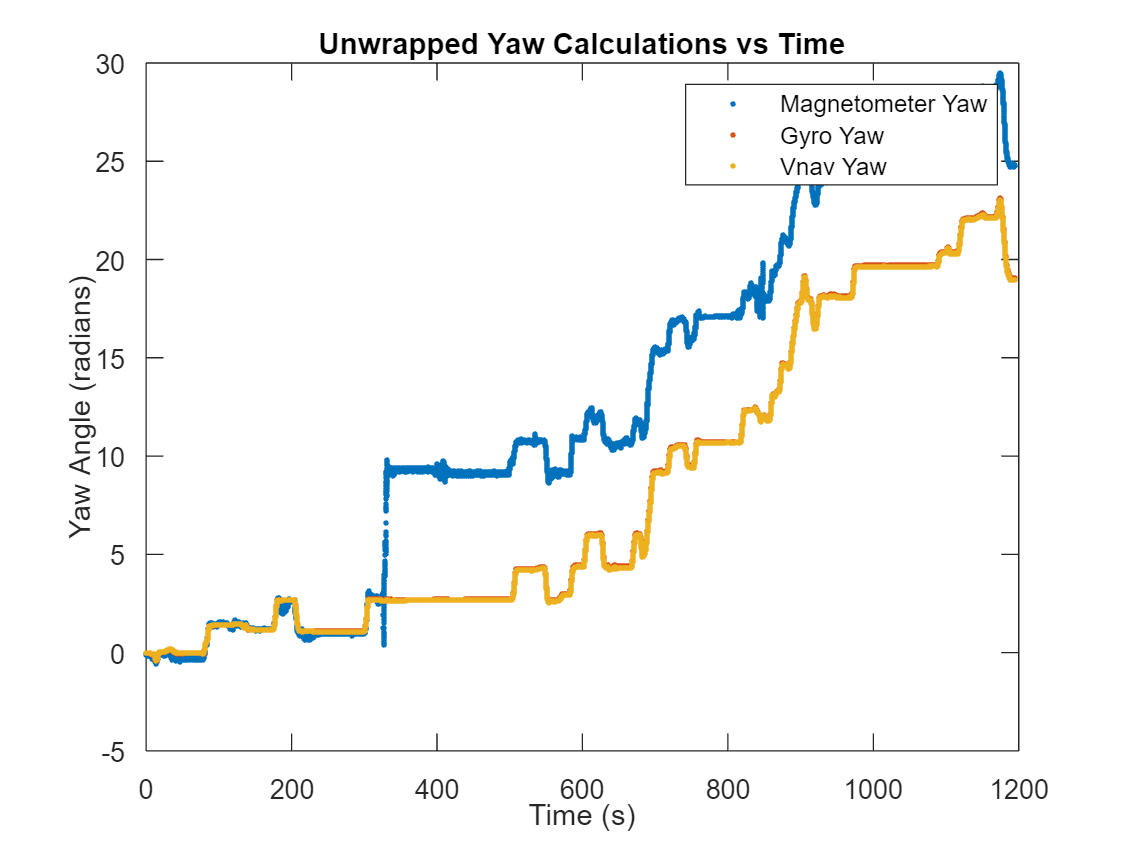

% Okay, so the code from the unwrapped sections are ~bad~ (atleast for the
% magnetometer. But seeing as we have ~many turns~ and much data, I'm going
% to truncate the first aprox. 5-6mins of data to remove that drift error.
% and use the data from index 13,500 and on -- hopefully that'll correct
% things

errorindex = 13880;
tourlistlength = 47809;

time2 = time(errorindex:tourlistlength);
time2 = time2-time2(1);
MagX_tour2 = MagX_tour(errorindex:tourlistlength);
MagY_tour2 = MagY_tour(errorindex:tourlistlength);

mag_yaw_raw = atan2(-MagY_tour2,MagX_tour2);

%%%%% CALIBRATED YAW CALC
% now apply corrections...

% first, translate
xt_tour = MagX_tour2 - X0;
yt_tour = MagY_tour2 - Y0;

% then, rotate
alpha = phi;
R  = [cos(alpha) -sin(alpha); sin(alpha)  cos(alpha)];
rCoords = R*[xt_tour' ; yt_tour'];   
xr_tour = rCoords(1,:)';      
yr_tour = rCoords(2,:)'; 
% then squish to circle
xsquish_tour = xr_tour*squish_ratio;
ysquish_tour = yr_tour;

mag_yaw_corrected = atan2(-ysquish_tour,xsquish_tour);

hold off


uw_mag_yaw_raw = unwrap(wrapToPi(mag_yaw_raw));
uw_mag_yaw_corrected = unwrap(wrapToPi(mag_yaw_corrected));

plot(time2,uw_mag_yaw_raw,'.');
title('Raw and Calibrated Magnetometer Yaw of Boston Tour vs Time')
xlabel('Time (s)')
ylabel('Yaw (radians)')

hold on
plot(time2,uw_mag_yaw_corrected,'.')
legend('Raw Mag Yaw','Calibrated Mag Yaw')
hold off

NOTE ON ABOVE: Might want to have wrapped mag yaw raw vs calibrated instead of unwrapped graphed. But, continuing...

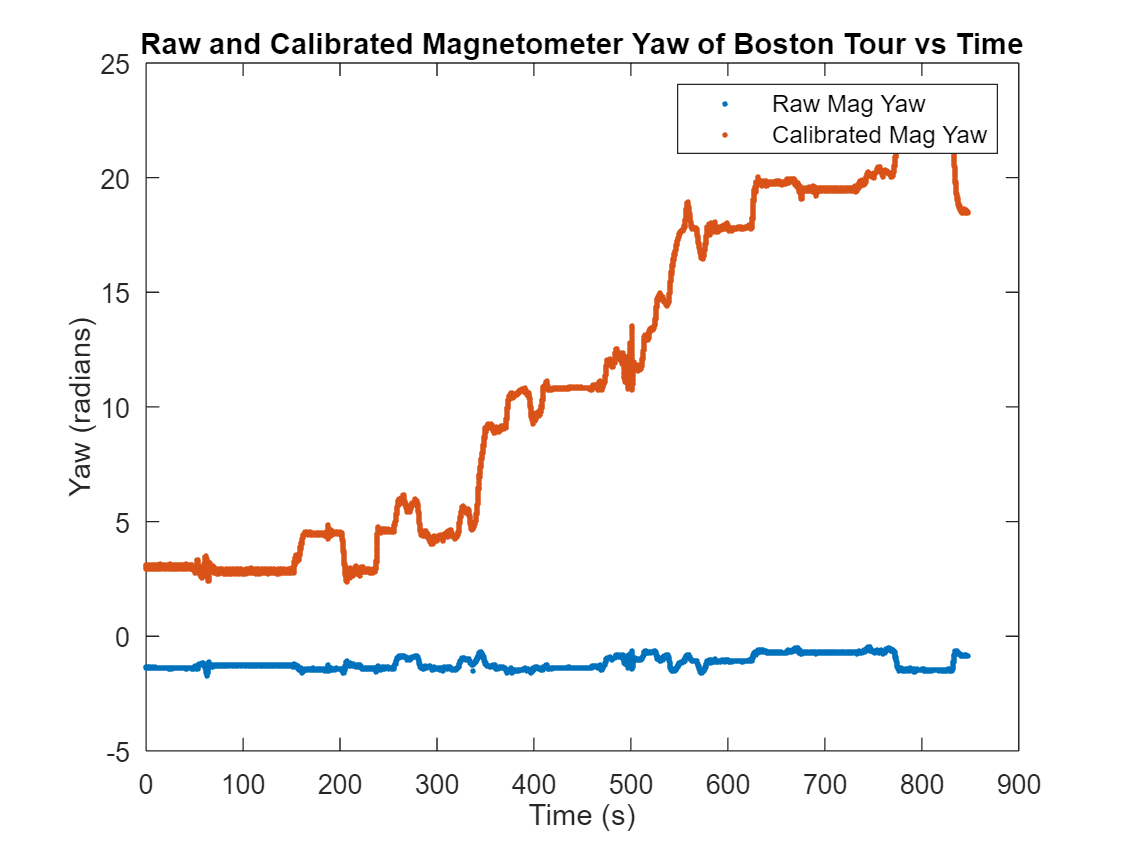

hold off

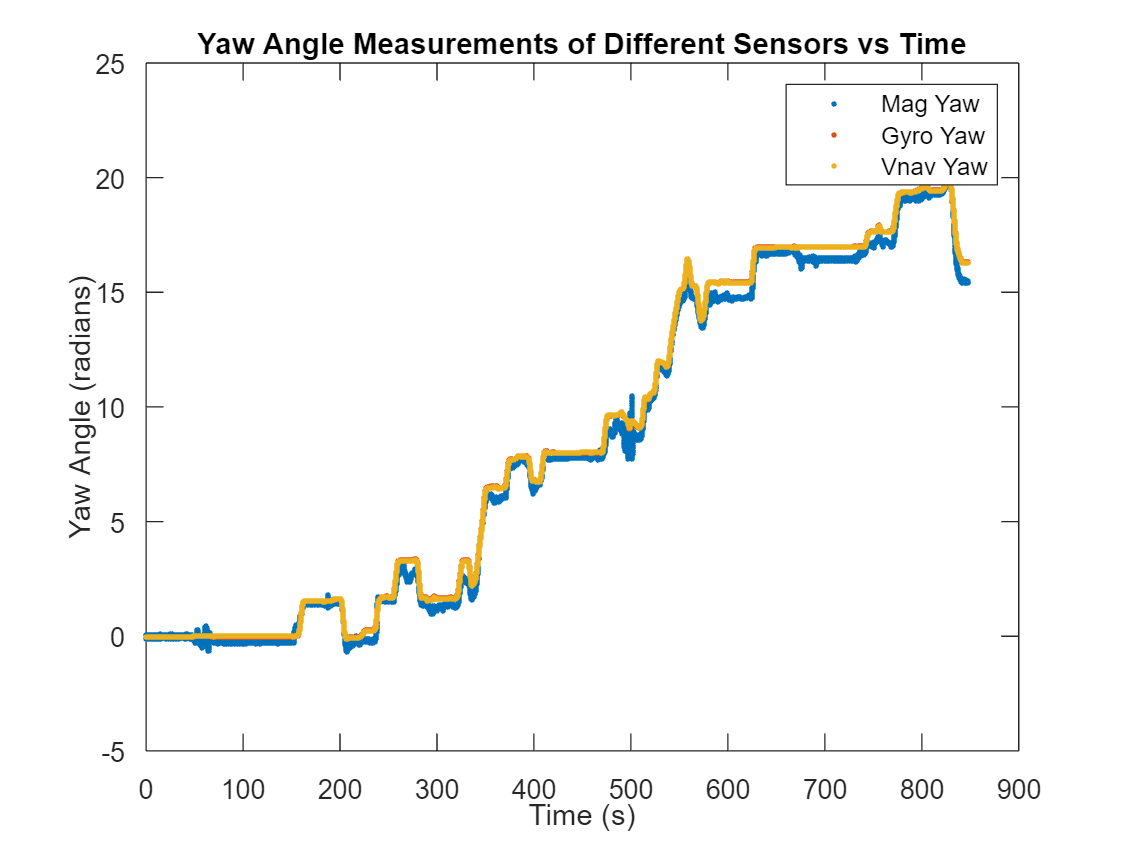


uw_mag_yaw_corrected = uw_mag_yaw_corrected - uw_mag_yaw_corrected(1);
plot(time2,uw_mag_yaw_corrected,'.')
title('Yaw Angle Measurements of Different Sensors vs Time')
xlabel('Time (s)')
ylabel('Yaw Angle (radians)');
hold on

gyro_yaw = yaw_gyro(errorindex:tourlistlength);

gyro_yaw = gyro_yaw - gyro_yaw(1);
w_gyro_yaw = wrapToPi(gyro_yaw);
plot(time2,gyro_yaw,'.');


w_Vnav_yaw = wrapToPi(eulerpositions(errorindex:tourlistlength,3));
uw_Vnav_yaw = unwrap(w_Vnav_yaw);

uw_Vnav_yaw = uw_Vnav_yaw - uw_Vnav_yaw(1);

plot(time2, uw_Vnav_yaw, '.');

legend('Mag Yaw','Gyro Yaw','Vnav Yaw');
hold off

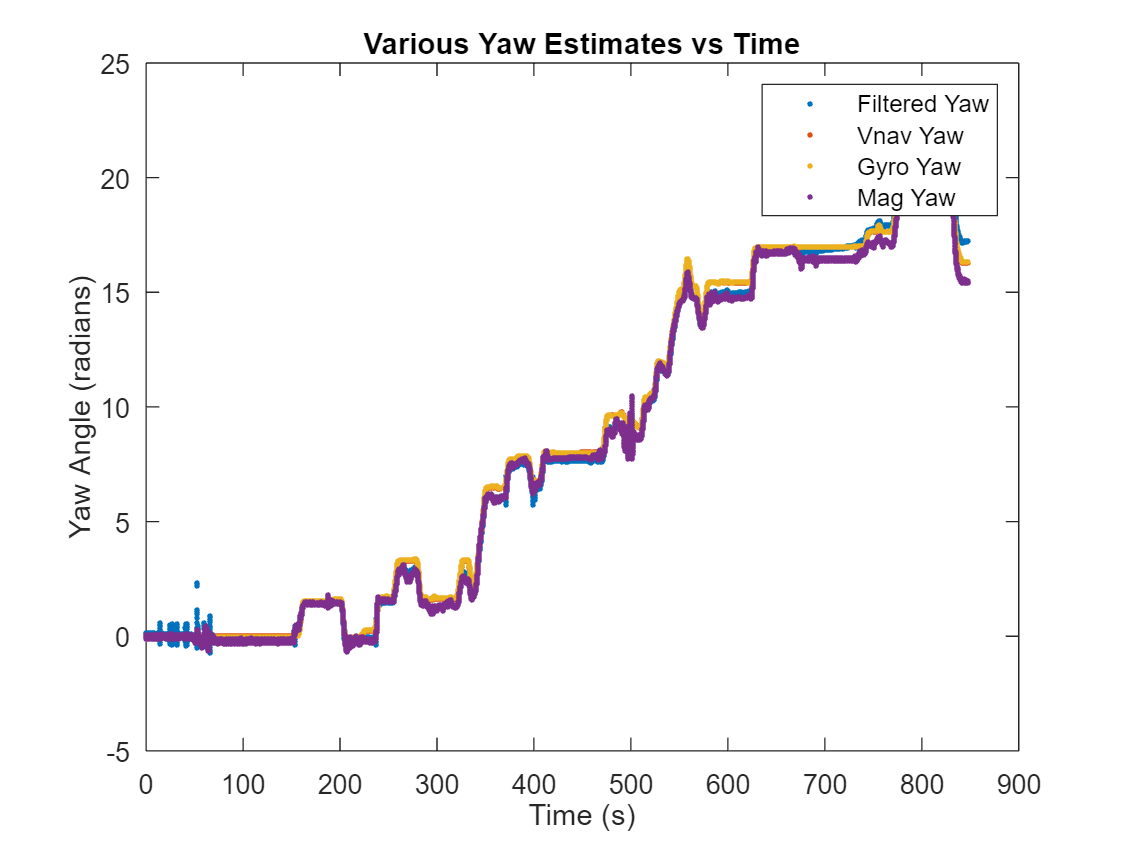

% errors currently between magnetometer yaw and gyro yaw w/ vectornav yaw

errorMag = mean(Vnav_yaw_unwrapped - unwrapped_mag_yaw_corrected);
errorGyro = mean(Vnav_yaw_unwrapped - yaw_gyro);

gyro_wrapped_yaw = wrapped_gyro_yaw(errorindex:tourlistlength);


% filtering
fs = 40; % sample rate, in Hz

fpasshigh = .001;
H = highpass(w_gyro_yaw,fpasshigh,fs);

%plot(time2,H,'.');
%title("HPF Gyro Yaw vs Time");
%plot(time2,w_gyro_yaw,'.');
%title("No Filter Wrapped Gyroscopic Yaw vs Time")




fpasslow = 17;% between 0-(40/2). 
L = lowpass(mag_yaw_corrected,fpasslow,fs); % originally did it with wrappingMagYaw_corrected, try yaw_corrected

%plot(time2,L,'.');
%title("LPF Mag Yaw vs Time");
%plot(time2,mag_yaw_corrected,'.');% originally with wrappingMagYaw..., try yaw_corrected
%title("No Filter Mag Yaw vs Time")








UH = unwrap(H);
UL = unwrap(L);
%plot(time2,UH,'.');
%title("Unwrapped HPF Gyro Yaw")
%plot(time2,UL,'.');
%title("Unwrapped LPF Gyro Yaw")
%J = H+L;
J=(UH+UL)/2;
%J = wrapToPi(J);
%plot(time2, J,'.');
%title("wrapped calibrated yaw")
M = J;%unwrap(J);

M=M-M(1);
plot(time2,M,'.');
title("Various Yaw Estimates vs Time")
xlabel('Time (s)')
ylabel('Yaw Angle (radians)')
hold on
plot(time2, uw_Vnav_yaw, '.');
plot(time2,gyro_yaw,'.');
plot(time2,uw_mag_yaw_corrected,'.');

legend('Filtered Yaw','Vnav Yaw','Gyro Yaw','Mag Yaw');
hold off

MOVING ON FROM THE FILTER STUFF, COME BACK TO TOMORROW!!!

Forward Velocity from Forward Acceleration (from accelerometer), before AND after calibration

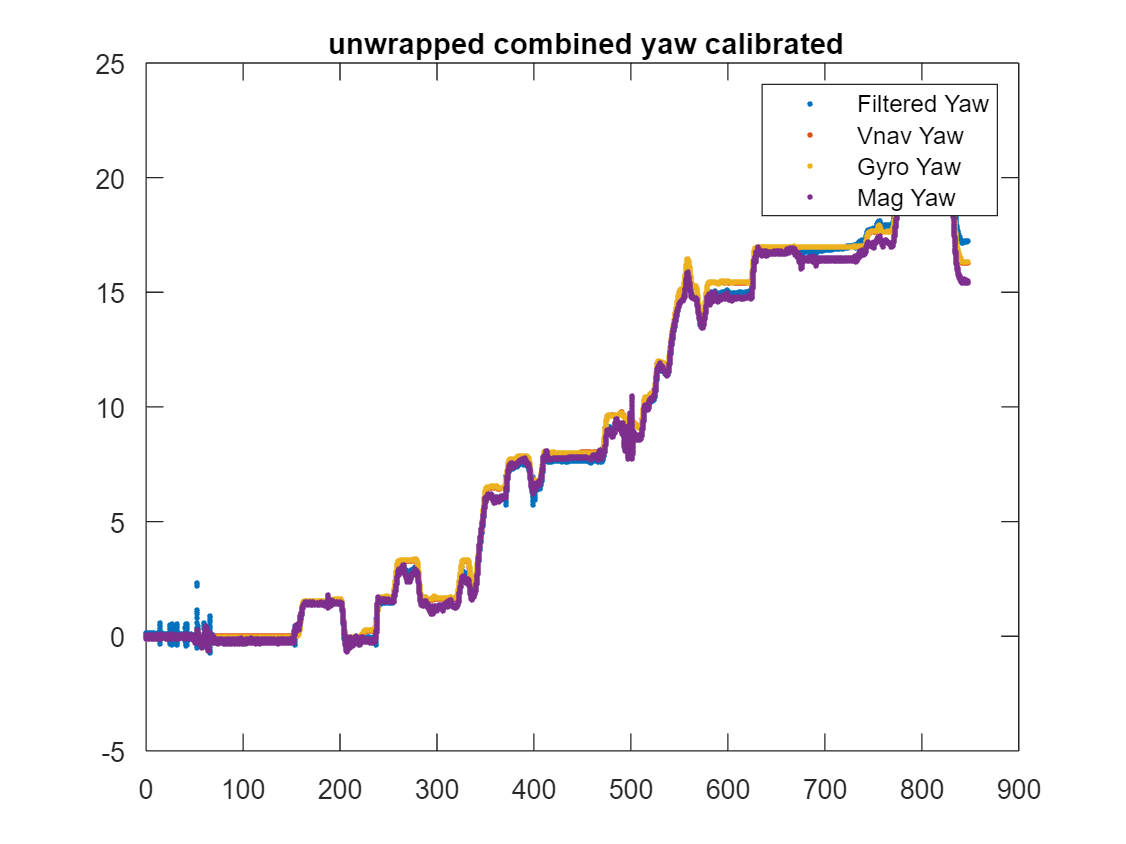


% first, do it before calibration

% load the data

    % forward acceleration (in x direction)
hold off

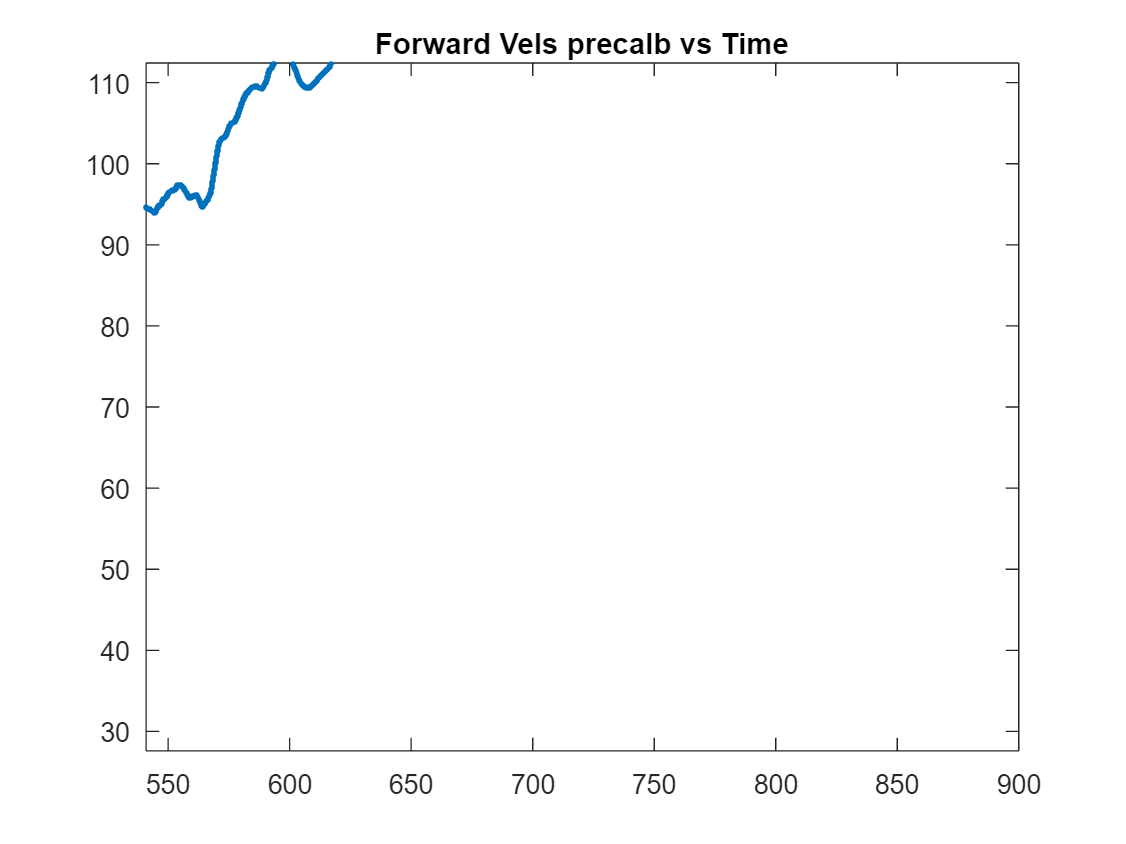

Xaccel = double(cellfun(@(m) m.Imu.LinearAcceleration.X,mstruct_tour_imu));
Xaccel = Xaccel(errorindex:tourlistlength);
Yaccel = double(cellfun(@(m) m.Imu.LinearAcceleration.Y,mstruct_tour_imu));
Yaccel = Yaccel(errorindex:tourlistlength);
Zaccel = double(cellfun(@(m) m.Imu.LinearAcceleration.Z,mstruct_tour_imu));
Zaccel = Zaccel(errorindex:tourlistlength);


w_Vnav_roll = wrapToPi(eulerpositions(errorindex:tourlistlength,1));
uw_Vnav_roll = unwrap(w_Vnav_roll);
w_Vnav_pitch = wrapToPi(eulerpositions(errorindex:tourlistlength,2));
uw_Vnav_pitch = unwrap(w_Vnav_pitch);


Accels = zeros(length(Xaccel),3);
Accels(:,1) = Xaccel;
Accels(:,2) = Yaccel;
Accels(:,3) = Zaccel;



% hold off
% %scatter(time, fwdvels_gyro, '.');
% title('Forward Speed from Forward Acceleration vs Time') 
% xlabel('Time (s)')
% ylabel('Speed (m/s)')
% 
% 
%plot(time,fwdaccel,'.')
F = cumtrapz(time2,Xaccel);
plot(time2,F,'.');
title('Forward Vels precalb vs Time');
hold off






% Accels_calibrated = zeros(length(time2),3);
% Vnav_angles = zeros(length(time2),3);% x,y,z ;;;roll,pitch,yaw respectively
% Vnav_angles(:,1) = w_Vnav_roll;
% Vnav_angles(:,2) = w_Vnav_pitch;
% Vnav_angles(:,3) = w_Vnav_yaw;
% % since rotx,roty,rotz commands require degrees, need to convert radians to
% % degrees
% Vnav_angles = Vnav_angles*180/pi;
% 
% for i = 1:length(time2);
%     thetax = Vnav_angles(i,1);
%     thetay = Vnav_angles(i,2);
%     thetaz = Vnav_angles(i,3);
%     Accels_calibrated(i,:) = Accels(i,:)*rotx(thetax)*roty(thetay);
% end




% above is velocities found from accelX before calibration. Need to apply 
% a rotation about pitch and roll to fix.






% hold off
 hold off

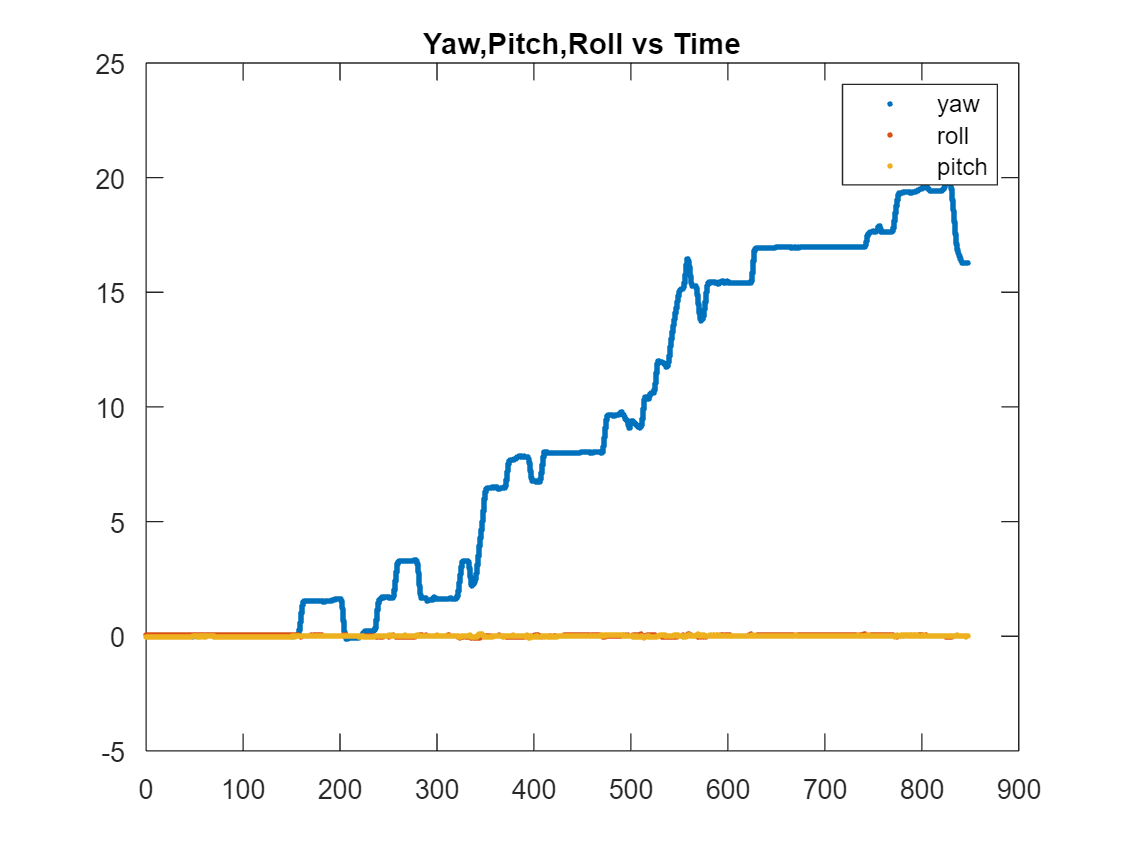

plot(time2,uw_Vnav_yaw,'.');
title('Yaw,Pitch,Roll vs Time')
hold on
plot(time2,uw_Vnav_roll,'.');
plot(time2,uw_Vnav_pitch,'.');
legend('yaw','roll','pitch')
hold off

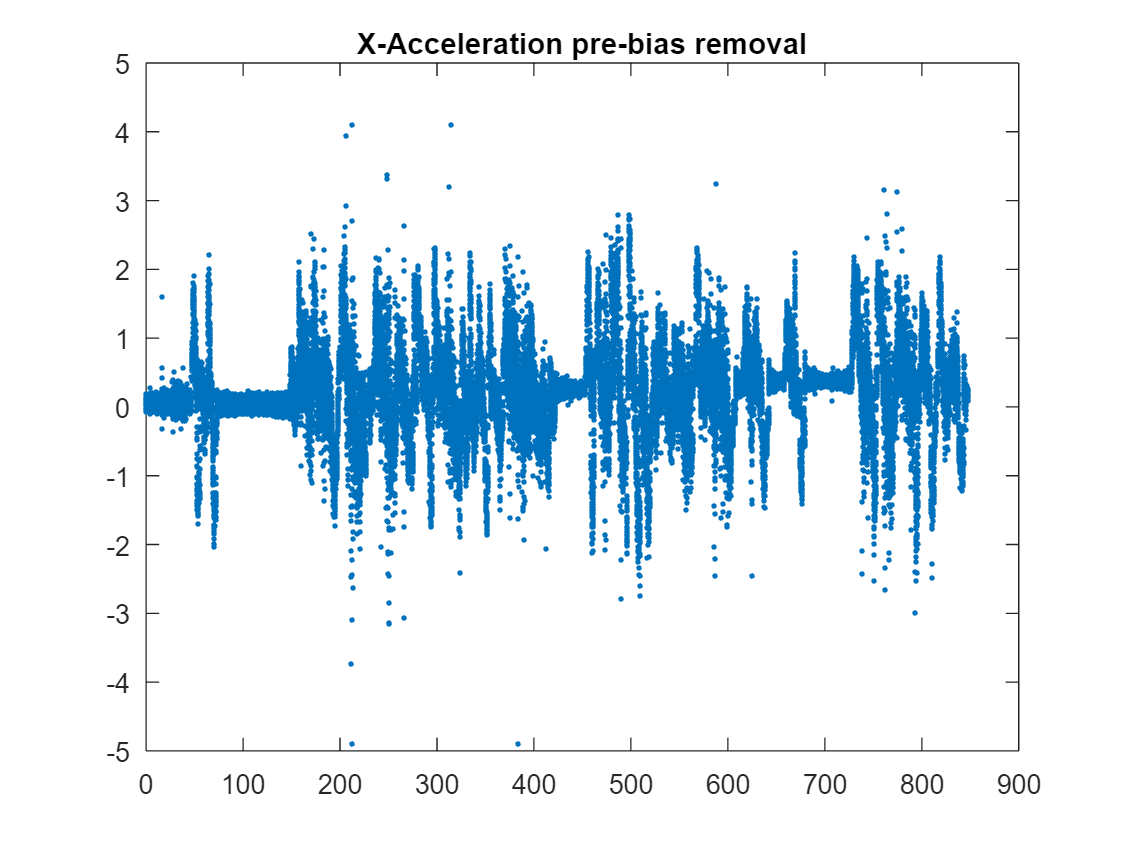

% okay, so the yaw, pitch, roll vs time graph shows that our sensor is
% aligned apropriately (no misalignment). With that, I should instead
% account for biases like Asjad has mentioned in response to Matt's
% comments


plot(time2, Accels(:,1),'.');
title('X-Acceleration pre-bias removal');

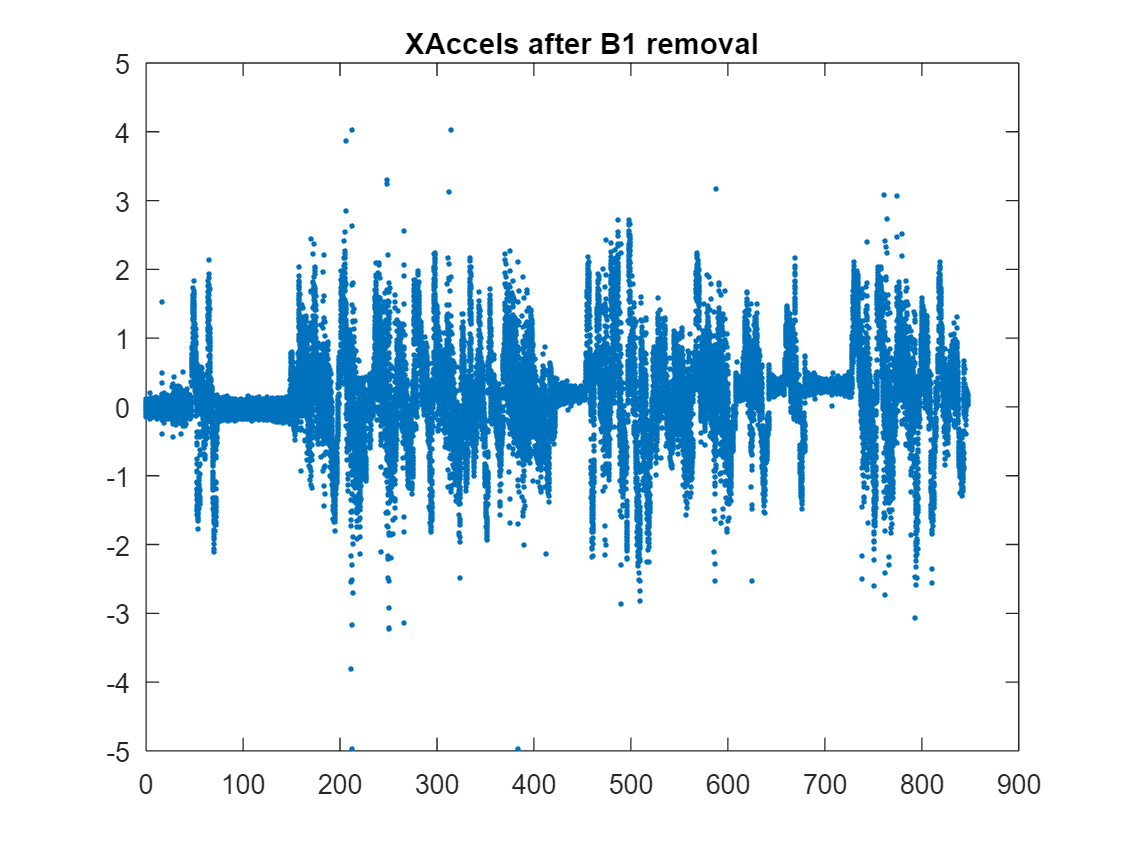


Bias1 = mean(Accels(1:1840,1));
XAccel_B1rem = Accels(:,1) - Bias1;
plot(time2,XAccel_B1rem,'.');
title('XAccels after B1 removal')

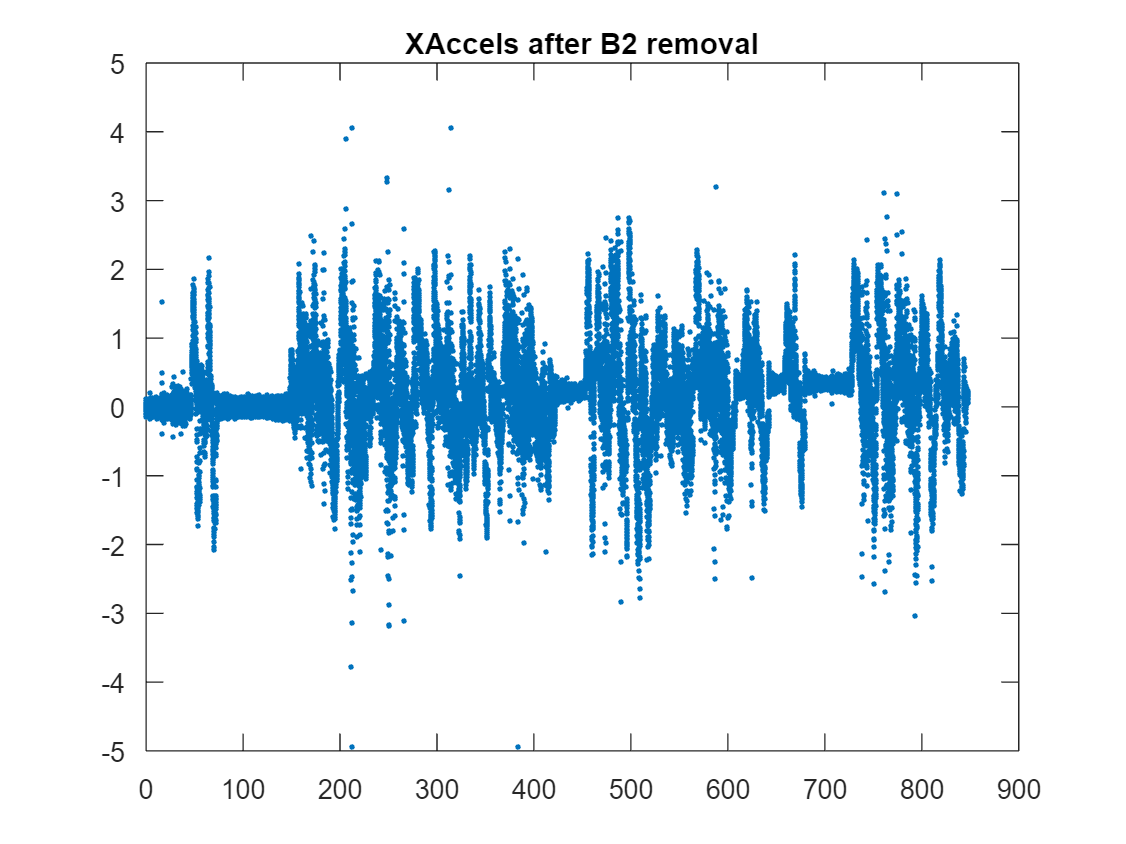



% further bias removals must only occur on future points (AKA, the points
% before and of bias 1's calculation).

Bias2 = mean(XAccel_B1rem(2945:5907));

XAccel_B2rem = zeros(length(XAccel_B1rem),1);
XAccel_B2rem(1:1840) = XAccel_B1rem(1:1840);
XAccel_B2rem(1841:length(XAccel_B2rem)) = XAccel_B1rem(1841:length(XAccel_B1rem)) - Bias2;

plot(time2,XAccel_B2rem,'.');
title('XAccels after B2 removal');

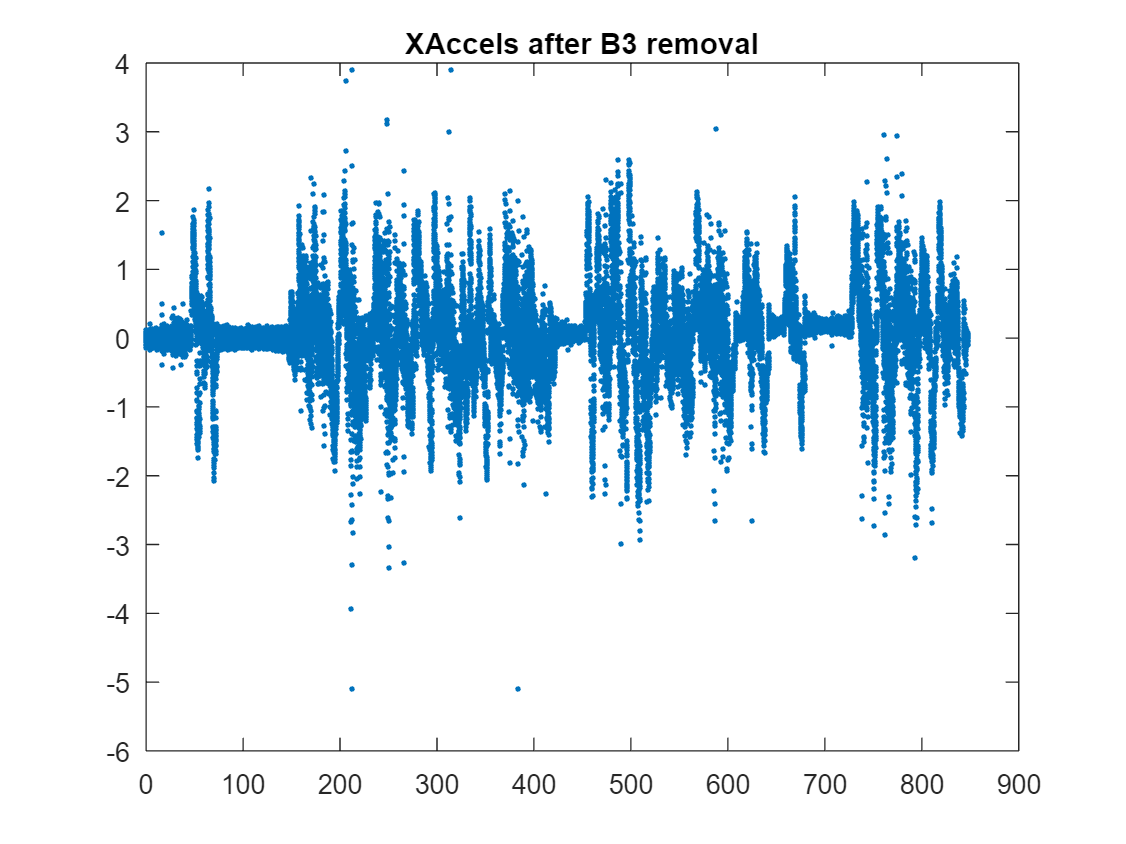


%%%%%%%%%%%%%%%%%%%%%%%%%
% Third Bias Removal
Bias3 = mean(XAccel_B2rem(7905:8020));

XAccel_B3rem = zeros(length(XAccel_B2rem),1);
XAccel_B3rem(1:5907) = XAccel_B2rem(1:5907);
XAccel_B3rem(5908:length(XAccel_B3rem)) = XAccel_B2rem(5908:length(XAccel_B2rem)) - Bias3;

plot(time2,XAccel_B3rem,'.');
title('XAccels after B3 removal');

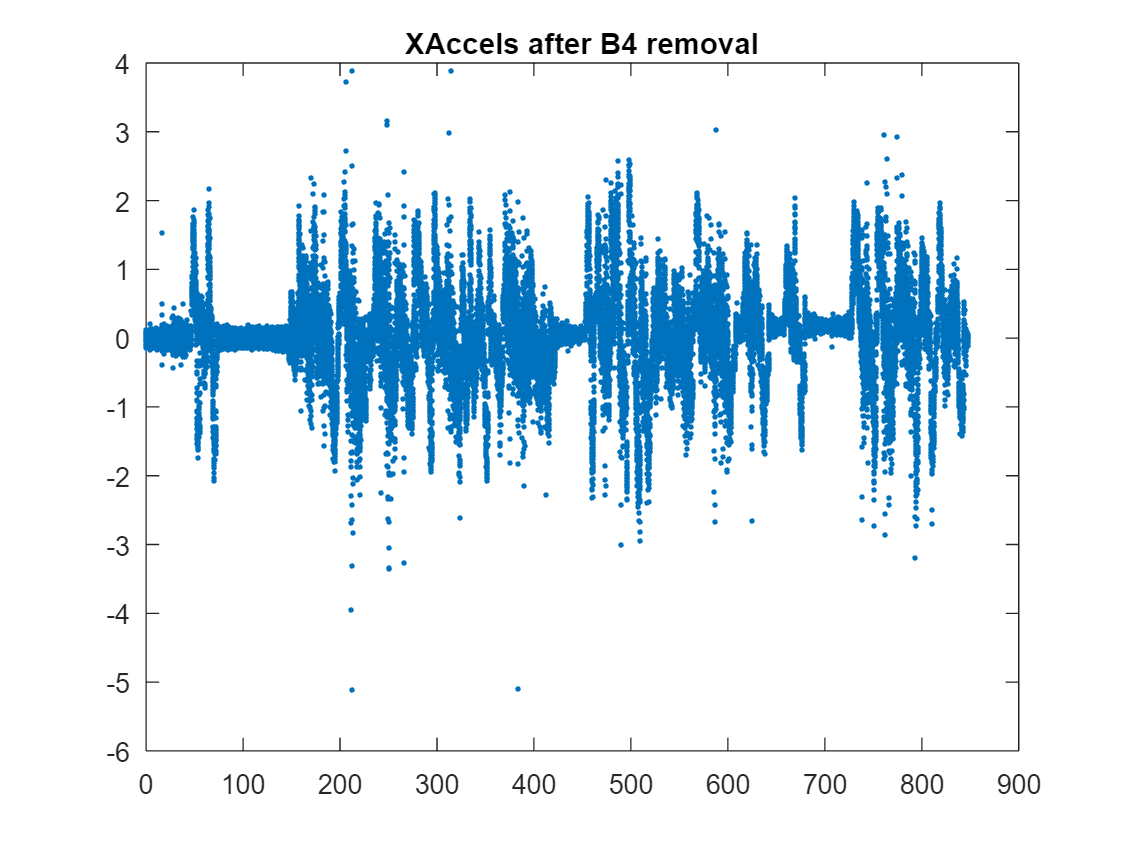


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%



% Fourth Bias removal
% originally 16904
%Bias4 = mean(XAccel_B3rem(17449:18129))-.001;
Bias4 = .01;%mean(XAccel_B3rem(9114:9360));
XAccel_B4rem = zeros(length(XAccel_B3rem),1);
XAccel_B4rem(1:8020) = XAccel_B3rem(1:8020);
XAccel_B4rem(8021:length(XAccel_B4rem)) = XAccel_B3rem(8021:length(XAccel_B3rem)) - Bias4;

plot(time2,XAccel_B4rem,'.');
title('XAccels after B4 removal');

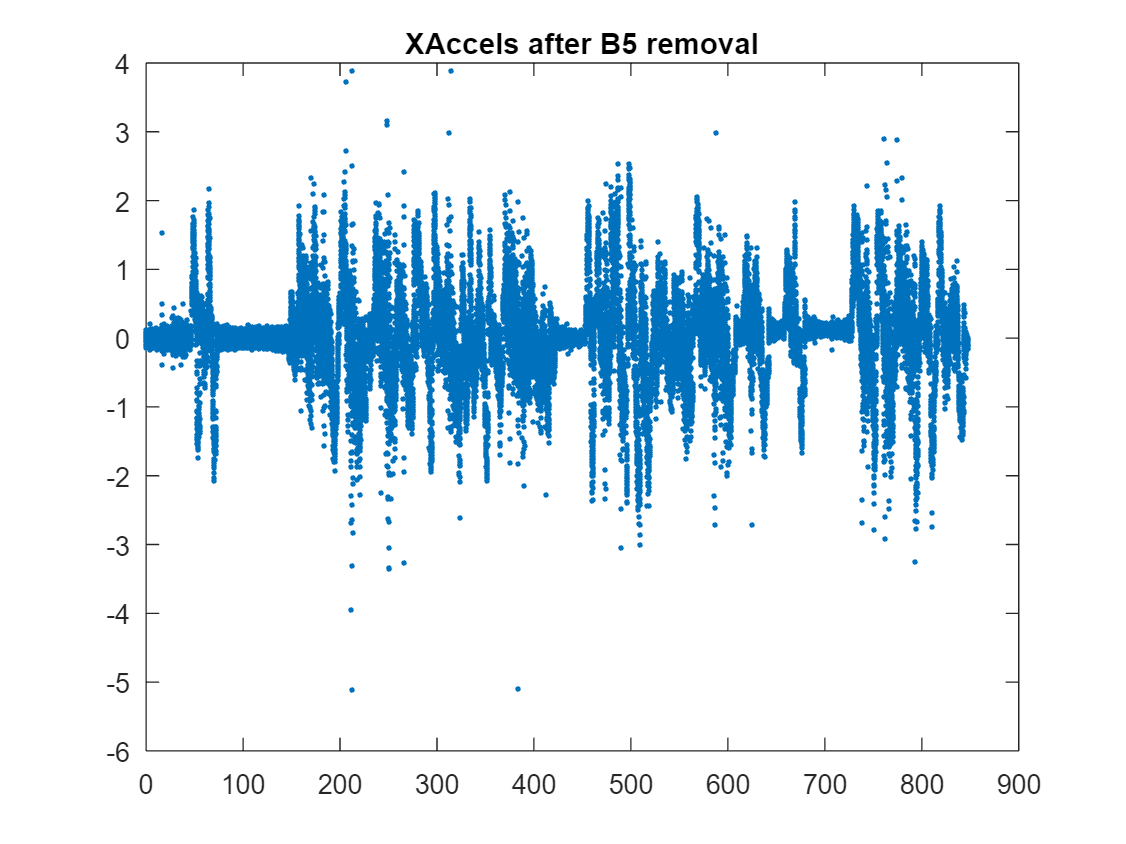



% Fifth Bias removal
% original .0525
Bias5 = .05;%mean(XAccel_B4rem(17000:18000));

XAccel_B5rem = zeros(length(XAccel_B4rem),1);
%XAccel_B5rem(1:9360) = XAccel_B4rem(1:9360);
% XAccel_B5rem(9361:length(XAccel_B5rem)) = XAccel_B4rem(9361:length(XAccel_B4rem)) - Bias5;
XAccel_B5rem(1:16999) = XAccel_B4rem(1:16999);
XAccel_B5rem(17000:length(XAccel_B5rem)) = XAccel_B4rem(17000:length(XAccel_B4rem)) - Bias5;

plot(time2,XAccel_B5rem,'.');
title('XAccels after B5 removal');

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% Sixth Bias removal

Bias6 = -.2%mean(XAccel_B5rem(20940:20945)));

Bias6 = -0.2000

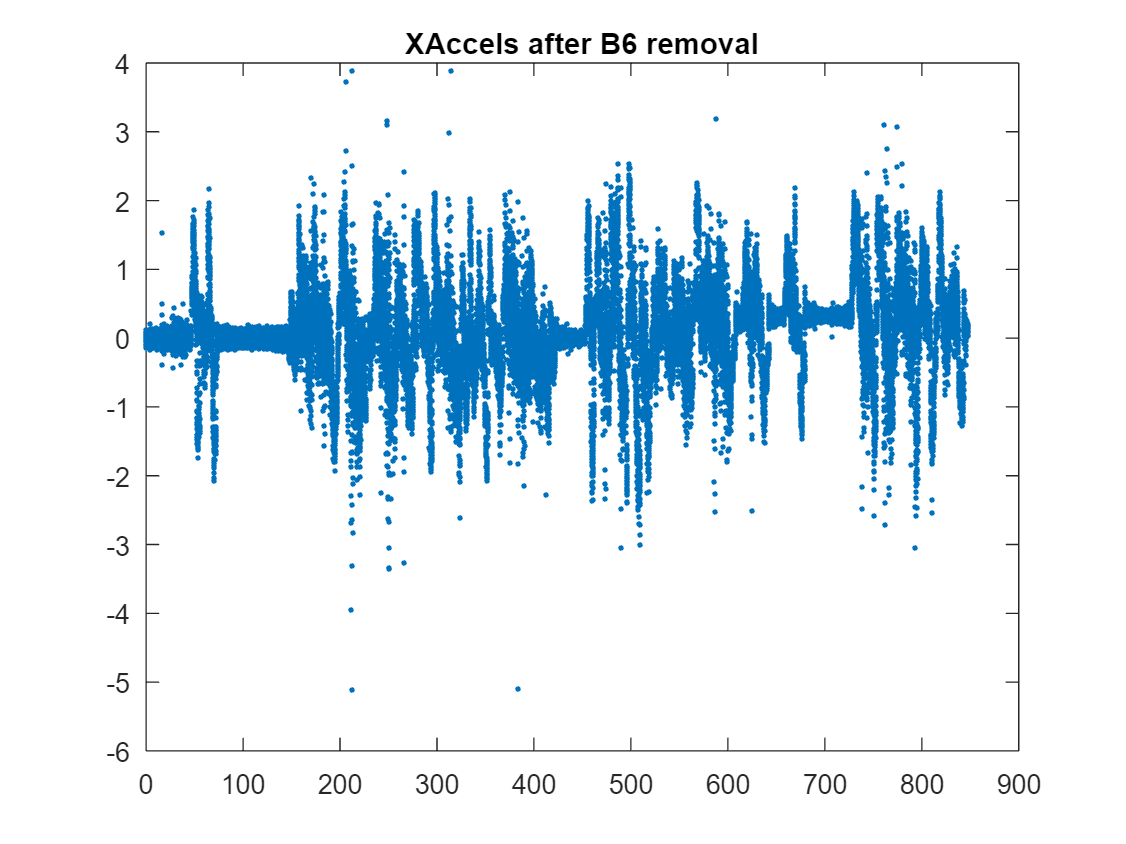


XAccel_B6rem = zeros(length(XAccel_B5rem),1);
XAccel_B6rem(1:20475) = XAccel_B5rem(1:20475);
XAccel_B6rem(20476:length(XAccel_B6rem)) = XAccel_B5rem(20476:length(XAccel_B5rem)) - Bias6;

plot(time2,XAccel_B6rem,'.');
title('XAccels after B6 removal');



% Seventh Bias removal

Bias7 = .12%mean(XAccel_B6rem(22649:22653)));

Bias7 = 0.1200

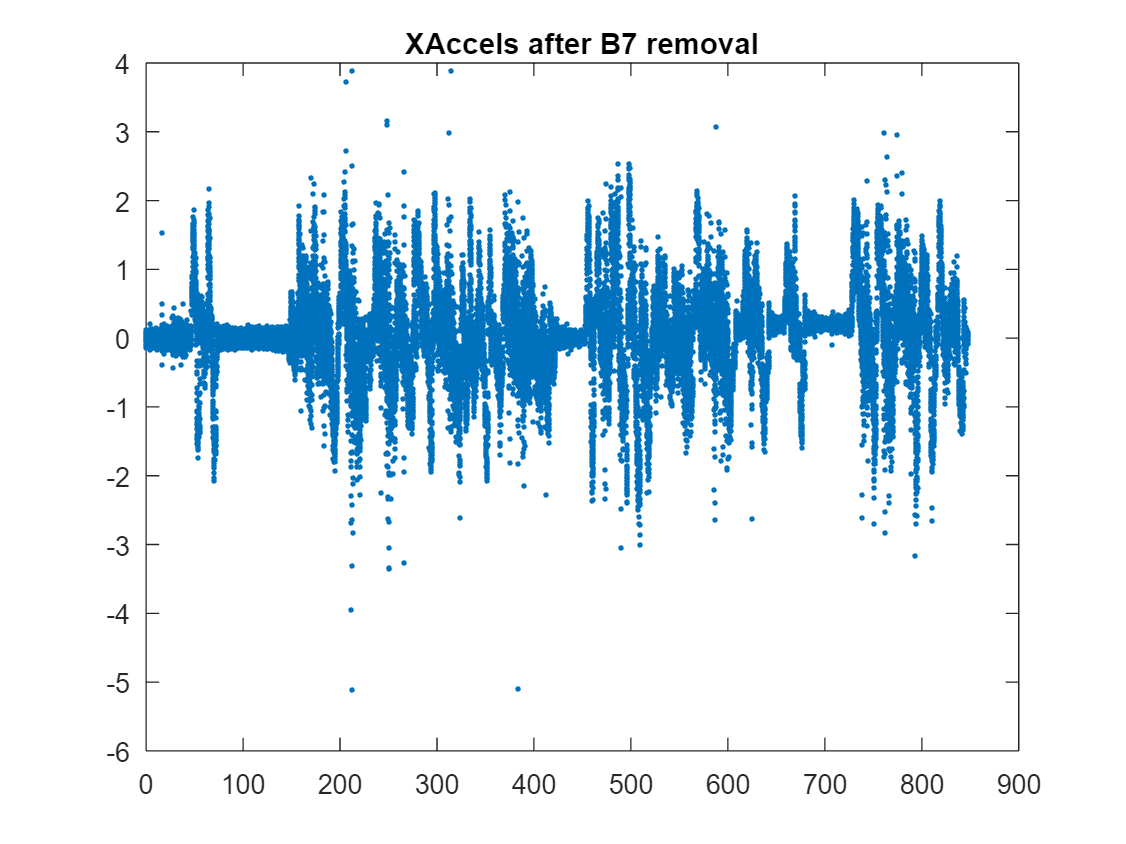


XAccel_B7rem = zeros(length(XAccel_B6rem),1);
XAccel_B7rem(1:20945) = XAccel_B6rem(1:20945);
XAccel_B7rem(20946:length(XAccel_B7rem)) = XAccel_B6rem(20946:length(XAccel_B6rem)) - Bias7;

plot(time2,XAccel_B7rem,'.');
title('XAccels after B7 removal');



% 8th Bias removal

Bias8 = .14%mean(XAccel_B7rem(24388:24616)));

Bias8 = 0.1400

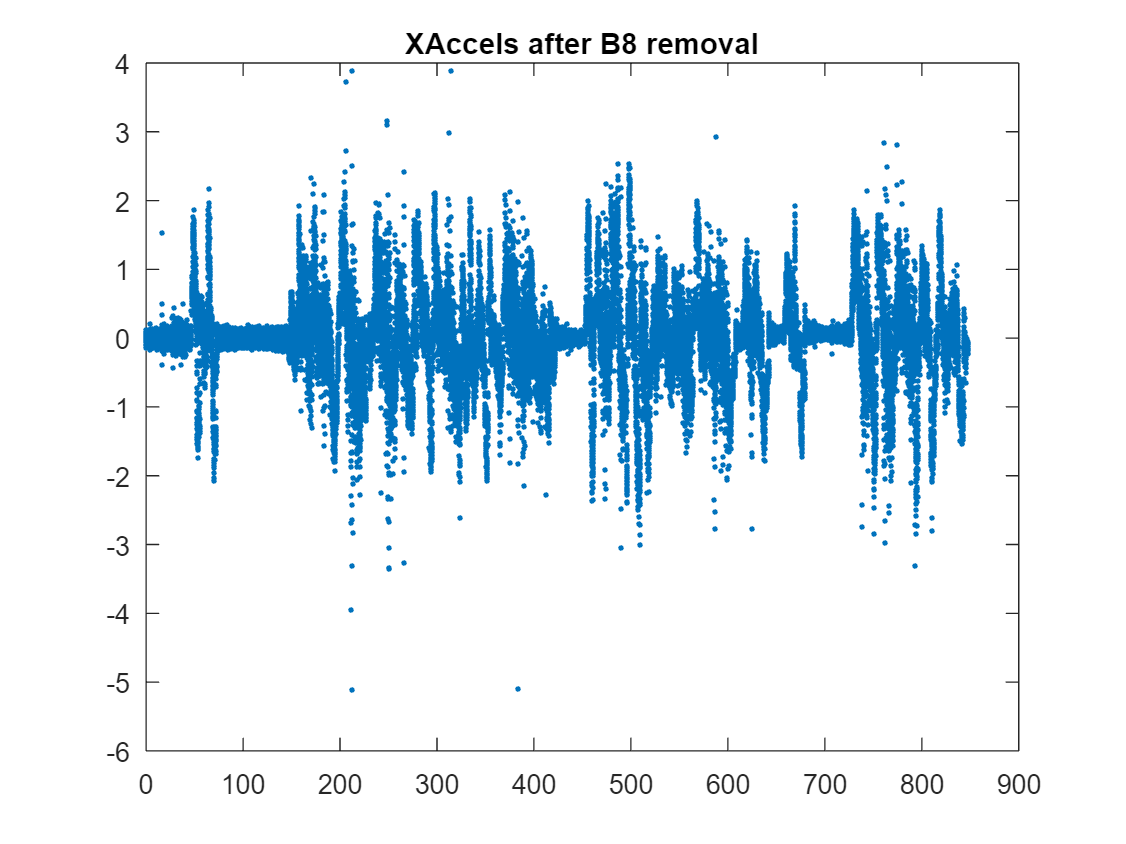


XAccel_B8rem = zeros(length(XAccel_B7rem),1);
XAccel_B8rem(1:22653) = XAccel_B7rem(1:22653);
XAccel_B8rem(22654:length(XAccel_B8rem)) = XAccel_B7rem(22654:length(XAccel_B7rem)) - Bias8;

plot(time2,XAccel_B8rem,'.');
title('XAccels after B8 removal');


% 9th Bias removal

Bias9 = .005%mean(XAccel_B7rem(24388:24616)));

Bias9 = 0.0050

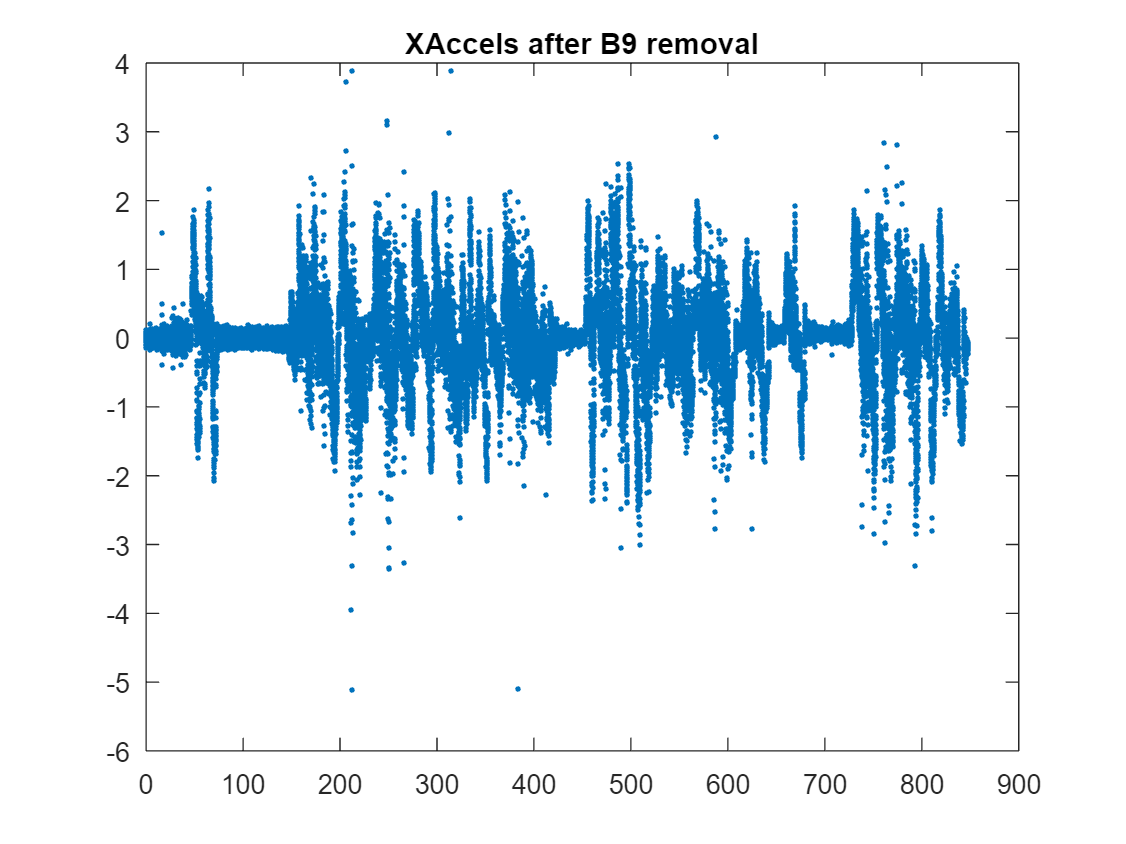


XAccel_B9rem = zeros(length(XAccel_B8rem),1);
XAccel_B9rem(1:24615) = XAccel_B8rem(1:24615);
XAccel_B9rem(24616:length(XAccel_B9rem)) = XAccel_B8rem(24616:length(XAccel_B8rem)) - Bias9;

plot(time2,XAccel_B9rem,'.');
title('XAccels after B9 removal');

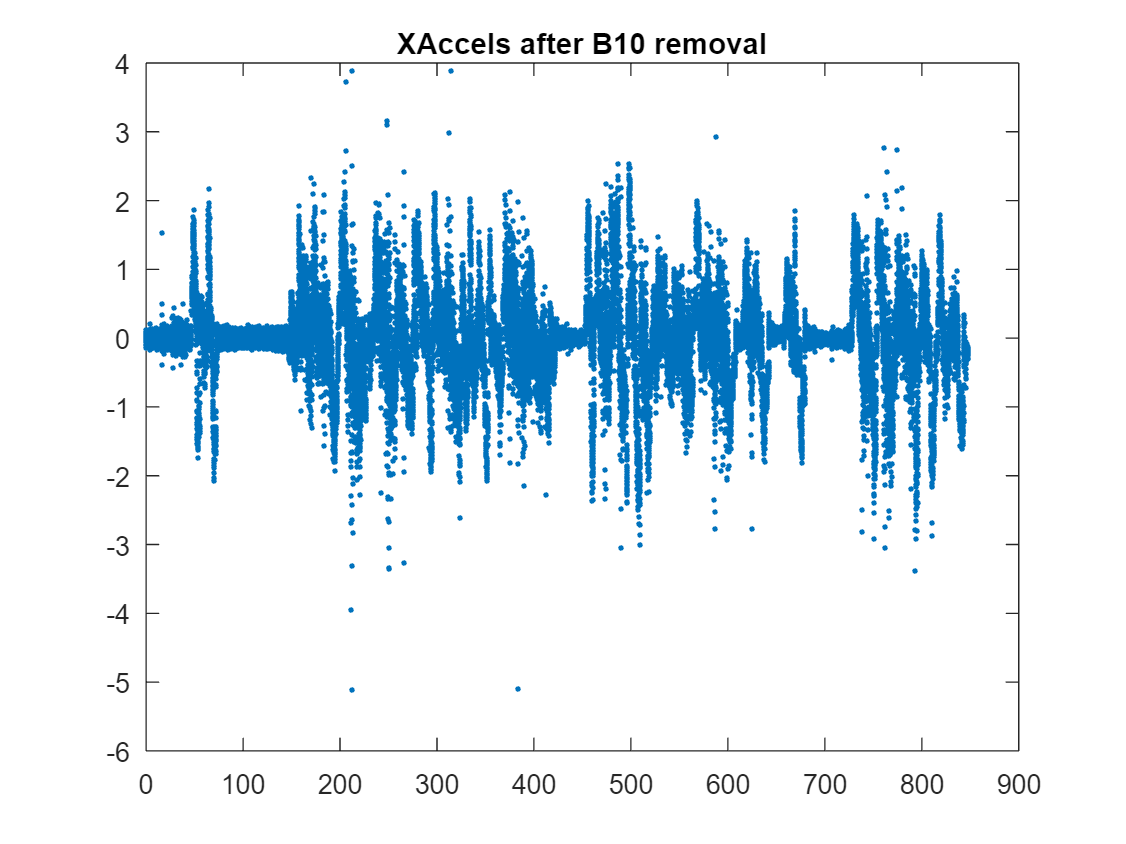


% 10th Bias removal

Bias10 = mean(XAccel_B9rem(27300:29000));

XAccel_B10rem = zeros(length(XAccel_B9rem),1);
XAccel_B10rem(1:26329) = XAccel_B9rem(1:26329);
XAccel_B10rem(26320:length(XAccel_B10rem)) = XAccel_B9rem(26320:length(XAccel_B9rem)) - Bias10;

plot(time2,XAccel_B10rem,'.');
title('XAccels after B10 removal');

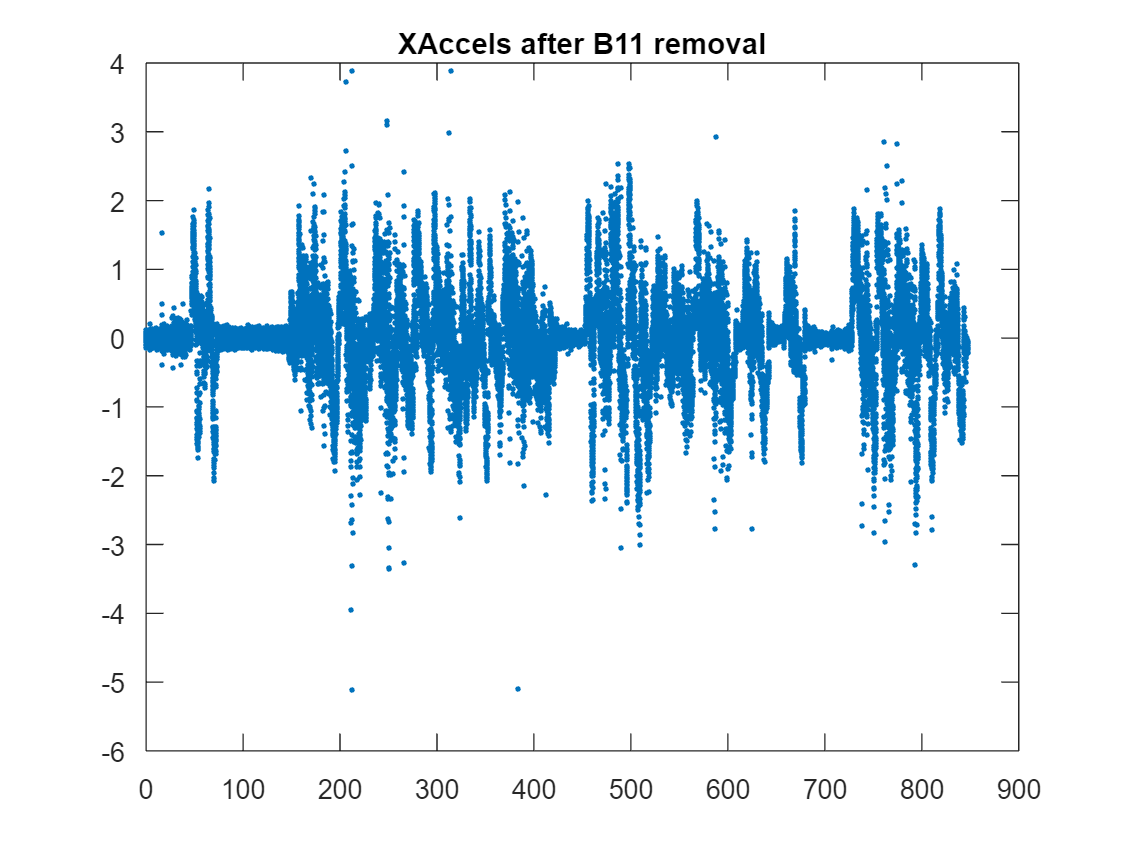



% 11th Bias removal
%-.174 original
Bias11 = -.09;%mean(XAccel_B10rem(32620:32660));

XAccel_B11rem = zeros(length(XAccel_B10rem),1);
XAccel_B11rem(1:29160) = XAccel_B10rem(1:29160);
XAccel_B11rem(29161:length(XAccel_B11rem)) = XAccel_B10rem(29161:length(XAccel_B10rem)) - Bias11;

plot(time2,XAccel_B11rem,'.');
title('XAccels after B11 removal');



% % Sixth Bias removal
% 
% Bias6 = mean(XAccel_B5rem(24252:24313));
% 
% XAccel_B6rem = zeros(length(XAccel_B5rem),1);
% XAccel_B6rem(1:24251) = XAccel_B5rem(1:24251);
% XAccel_B6rem(24252:length(XAccel_B6rem)) = XAccel_B5rem(24252:length(XAccel_B5rem)) - Bias6;
% 
% plot(time2,XAccel_B6rem,'.');
% title('XAccels after B6 removal');


## **I WILL CONTINUE THIS ONCE I HAVE THE GPS VELOCITY**

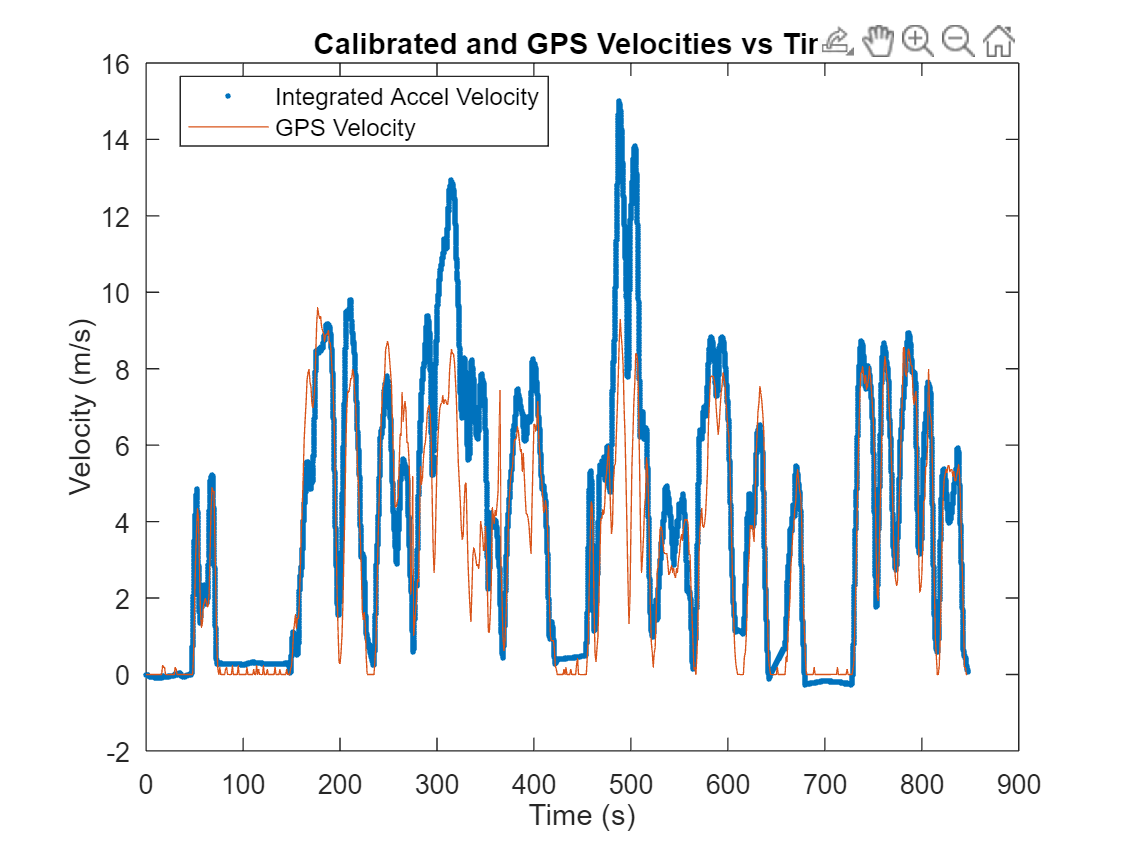

NewVels = cumtrapz(time2,XAccel_B11rem);


plot(time2,NewVels,'.');
title('Calibrated and GPS Velocities vs Time')
xlabel('Time (s)')
ylabel('Velocity (m/s)')
hold on



% need to find forward velocity from GPS
% UTM Easting and UTM Northing are in units of meters. They act essentially
% here as x and y values. Finding the distance between each point and then
% dividing by time will give 

% NOTE:GPS data was taken once ever second, NOT every second
secs_gps = double(cellfun(@(m) m.Header.Stamp.Sec,mstruct_tour_gps));
nsecs_gps = double(cellfun(@(m) m.Header.Stamp.Nsec,mstruct_tour_gps));
secs_gps = secs_gps - secs_gps(1);
nsecs_gps = nsecs_gps - nsecs_gps(1);
time_gps = secs_gps + (nsecs_gps * 10^-9);

easting = double(cellfun(@(m) m.UTMEasting,mstruct_tour_gps));
easting = easting-easting(1);
diffs_without_0point_easting = diff(easting);
eastingdifs = zeros(length(easting),1);
eastingdifs(2:length(easting)) = diffs_without_0point_easting;

northing = double(cellfun(@(m) m.UTMNorthing,mstruct_tour_gps)); 
northing = northing - northing(1);
diffs_without_0point_northing = diff(northing);
northingdifs = zeros(length(northing),1);
northingdifs(2:length(northing)) = diffs_without_0point_northing;


gps_distances = (northingdifs.^2 + eastingdifs.^2).^(0.5);
% so these are the distances between points and, again, since the
% differences in time are all one second, then doing [distance]/[time] is
% literally just all the gps_distances divided by 1s, soooooo

deltatime = 1;% gps gives vals every 1s
gps_vels = gps_distances/deltatime;

%%%%% NOTE: YOU HAVE TO CUT BEGINNING TO ACCOUNT FOR HOW YOU IGNORED
%%%%% BEGINNING OF IMU DATA.

time_gps_cut = time_gps(348:length(time_gps));
time_gps_cut = time_gps_cut - time_gps_cut(1);
gps_vels_cut = gps_vels(348:length(gps_vels));

plot(time_gps_cut,gps_vels_cut);

legend('Integrated Accel Velocity','GPS Velocity')

hold off

hold off

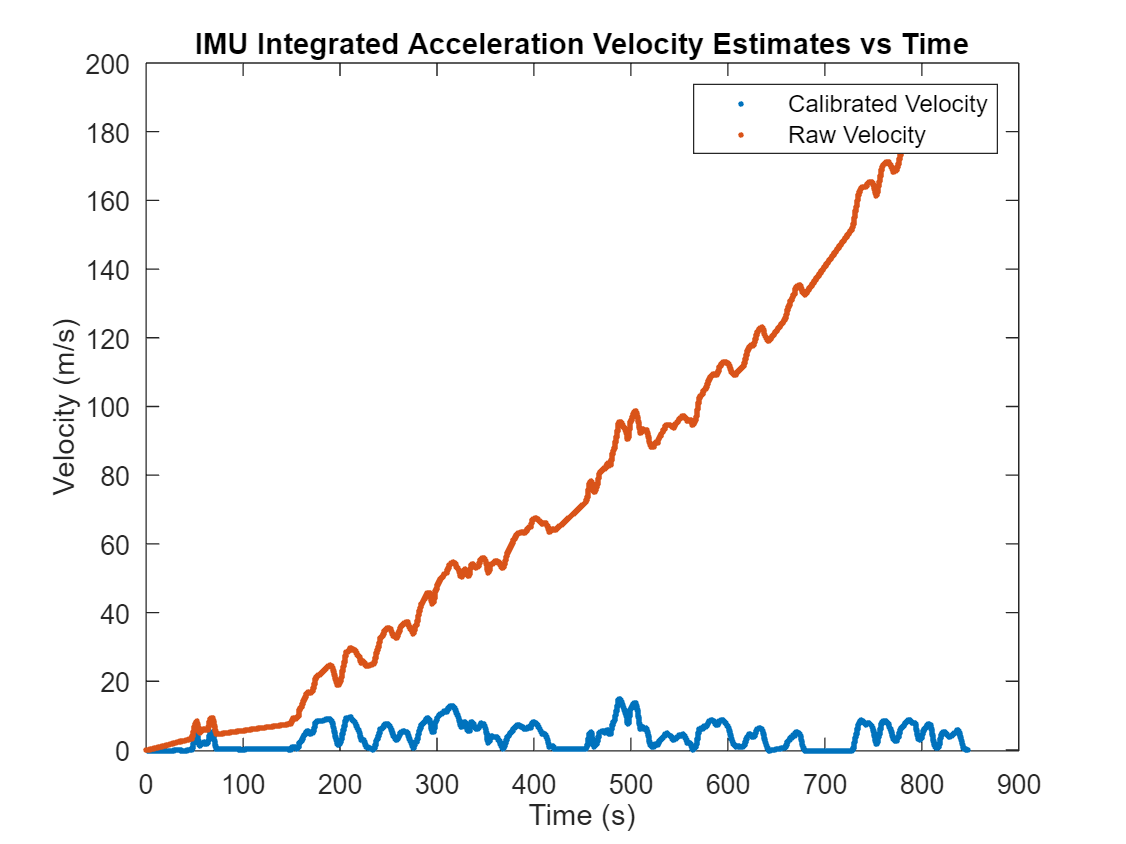

plot(time2,NewVels,'.')
title('IMU Integrated Acceleration Velocity Estimates vs Time')
xlabel('Time (s)')
ylabel('Velocity (m/s)')
hold on 
plot(time2,F,'.');
legend('Calibrated Velocity','Raw Velocity')
hold off

## That's good enough for accounting for biases in acceleration calculation of velocity. It lines up fairly well with velocity.

## NOW, CALCULATING POSITION PORTION

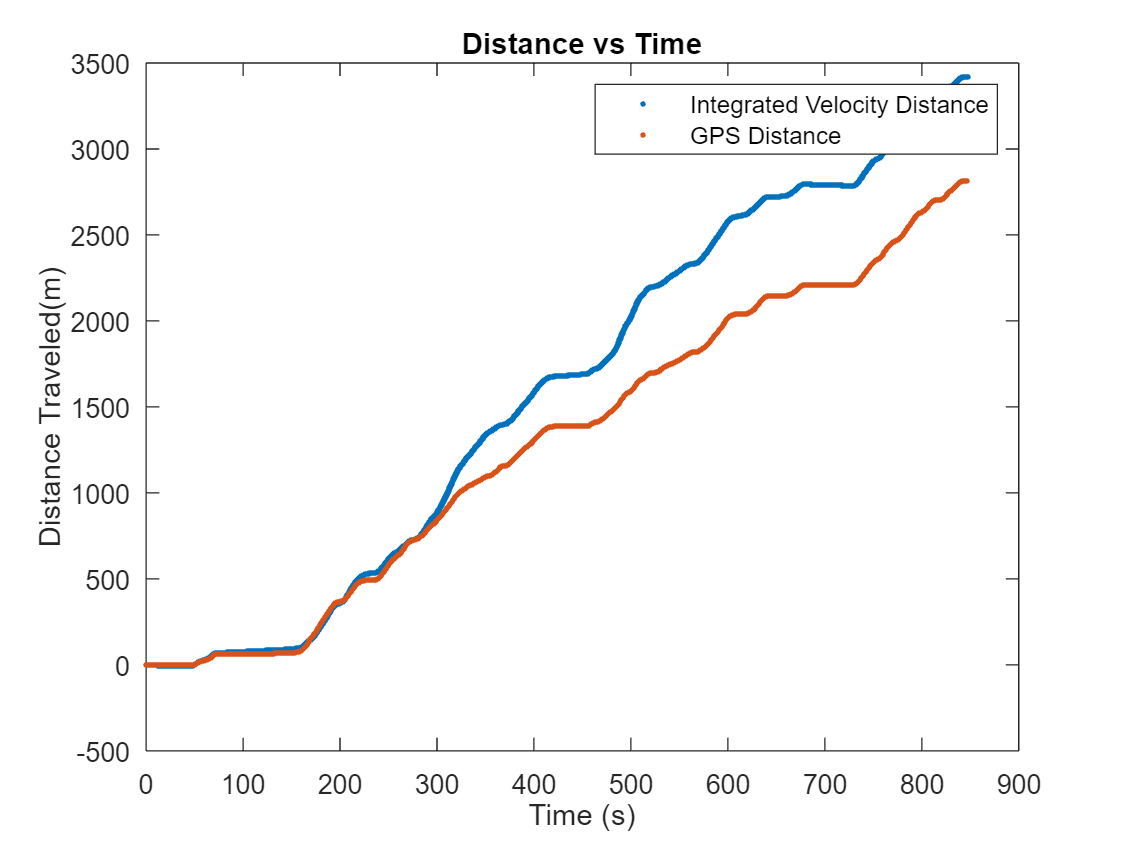



% displacement of velocity (calibrated...)

displacement_vel = cumtrapz(time2,NewVels);
displacement_gps = cumtrapz(time_gps_cut,gps_vels_cut);
plot(time2,displacement_vel,'.');
title('Distance vs Time')
xlabel('Time (s)');
ylabel('Distance Traveled(m)');
hold on
plot(time_gps_cut,displacement_gps,'.');
hold off
legend('Integrated Velocity Distance','GPS Distance')

THAT'S FOR OVERALL DISTANCE TRAVELED, I BELIEVE THE NEXT SECTION ASKS TO DIVIDE THESE NOW INTO COMPONENTS


% comparing omega*xdotobserved to ydotdotobserved
% my corrected x/fwd acceleration times my yaw is the former
% my recorded ydotdot observed is the latter


Ydotdotobs = Accels(:,2)

Ydotdotobs =    -0.5940
   -0.6080
   -0.5500
   -0.5500
   -0.6790
   -0.5220
   -0.5060
   -0.6190
   -0.5310
   -0.5490


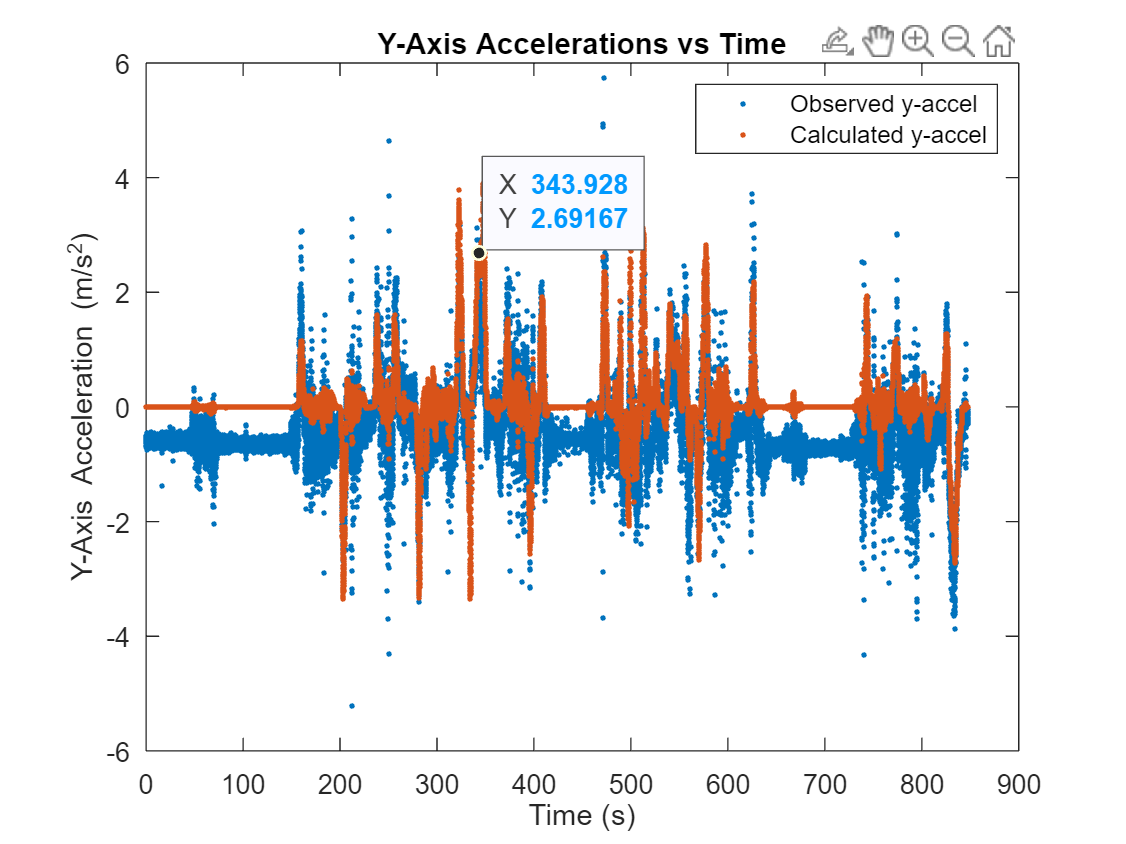

omega = yawrate_gyro(errorindex:tourlistlength); % 
xdotdot = XAccel_B11rem;
xdot = NewVels;
omegaxdot = omega.*xdot;


plot(time2,Ydotdotobs,'.');
title('Y-Axis Accelerations vs Time')
xlabel('Time (s)')
ylabel('Y-Axis Acceleration (m/s^2)')
hold on 
plot(time2,omegaxdot,'.');
legend('Observed y-accel','Calculated y-accel');
hold off


theta= -3.752

theta = -3.7520

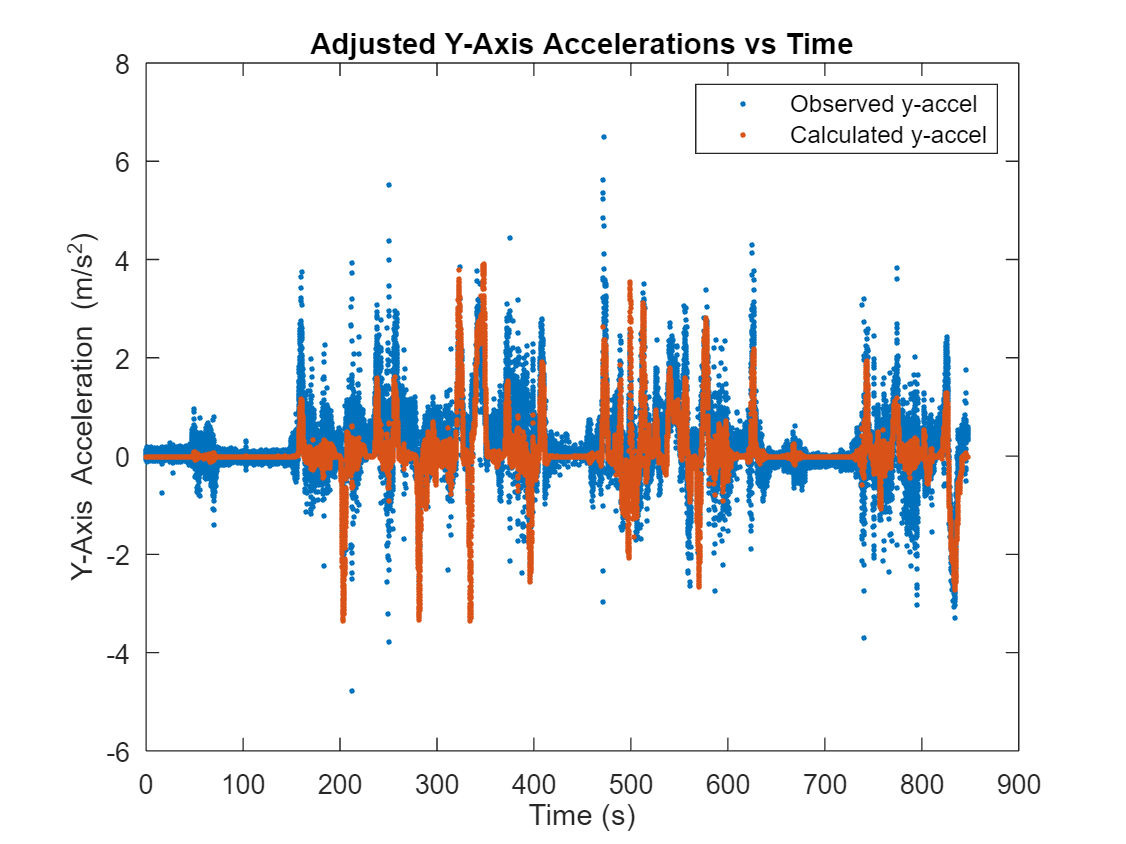

AdjAccels = Accels*rotx(theta);
Ydotdotnew = AdjAccels(:,2);

plot(time2,Ydotdotnew,'.');
title('Adjusted Y-Axis Accelerations vs Time')
xlabel('Time (s)')
ylabel('Y-Axis Acceleration (m/s^2)')
hold on 
plot(time2,omegaxdot,'.');
legend('Observed y-accel','Calculated y-accel');
hold off

## NOW THE HEADING STUFF W/ GPS Position and such

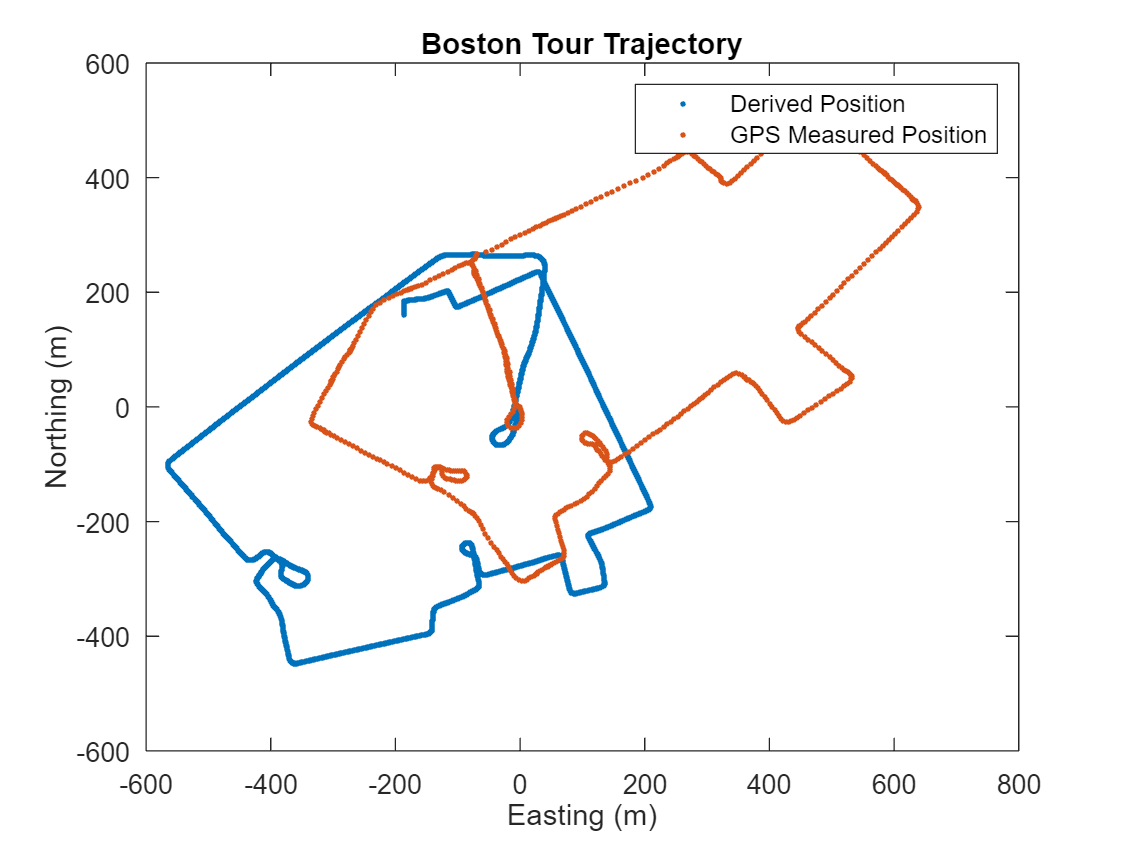

adjNewVels = NewVels - mean(NewVels);
adjYdotdotnew = Ydotdotnew - mean(Ydotdotnew);


Ve = NewVels .* sin(uw_mag_yaw_corrected);
Vn = NewVels .* cos(uw_mag_yaw_corrected);

Xe = cumtrapz(time2,Ve)*-1;
Xn = cumtrapz(time2,Vn)*-1;
Xe = Xe-Xe(length(Xe));
Xn = Xn-Xn(length(Xn));

% obsxpos = cumtrapz(time2,adjNewVels);
% obsyvel = cumtrapz(time2,adjYdotdotnew);
% % obsypos = cumtrapz(time2,obsyvel);
% hold off
% plot(Xe,Xn,'.');
% hold on
% plot(easting(348:length(easting)),northing(348:length(northing)),'.');
% legend('Derived Position','GPS Measured Position')
% hold off
% 














TheXAccel =double(cellfun(@(m) m.Imu.LinearAcceleration.X,mstruct_tour_imu));
TheYAccel =double(cellfun(@(m) m.Imu.LinearAcceleration.Y,mstruct_tour_imu));
TheZAccel =double(cellfun(@(m) m.Imu.LinearAcceleration.Z,mstruct_tour_imu));

TheAccels = zeros(length(TheXAccel),3);
TheAccels(:,1) = TheXAccel;
TheAccels(:,2) = TheYAccel;
TheAccels(:,3) = TheZAccel;

TheAccels = TheAccels*rotx(-3.752);



Ve1 = cumtrapz(time,TheXAccel) .* sin(yaw_gyro);
Vn1 = cumtrapz(time,TheXAccel) .* cos(yaw_gyro);
Ve = cumtrapz(time,TheAccels(:,1)) .* sin(yaw_gyro);
Vn = cumtrapz(time,TheAccels(:,1)) .* cos(yaw_gyro);

% 
% Xe1 = cumtrapz(time,Ve1);
% Xn1 = cumtrapz(time,Vn1);
% Xe1 = (Xe1-Xe1(length(Xe1)))/(.5*10^2);
% Xn1 = (Xn1-Xn1(length(Xn1)))/(.5*10^2);
% hold off
% plot(Xe1,Xn1,'.');
% title('Boston Tour Trajectory')
% xlabel('Easting (m)')
% ylabel('Northing (m)')
% hold on
% plot(easting,northing,'.');
% legend('Derived Position','GPS Measured Position')
% hold off


Xe = cumtrapz(time,Ve);
Xn = cumtrapz(time,Vn);
Xe = (Xe-Xe(length(Xe)))/(.5*10^2);
Xn = (Xn-Xn(length(Xn)))/(.5*10^2);
Xe = Xe;
Xn = Xn;



% obsxpos = cumtrapz(time2,adjNewVels);
% obsyvel = cumtrapz(time2,adjYdotdotnew);
% obsypos = cumtrapz(time2,obsyvel);
hold off

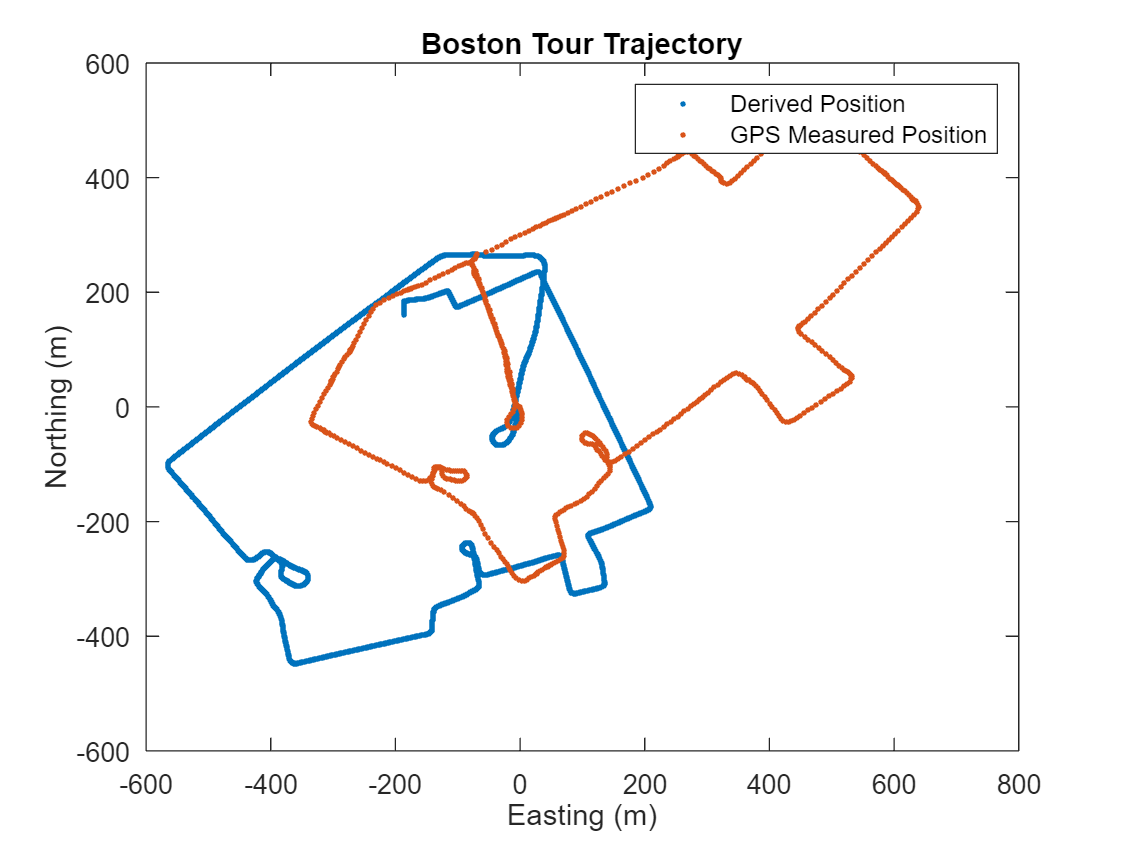

plot(Xe,Xn,'.');
title('Boston Tour Trajectory')
xlabel('Easting (m)')
ylabel('Northing (m)')
hold on
plot(easting,northing,'.');
legend('Derived Position','GPS Measured Position')
hold off



% section break --> offset xc calc that makes gps velocity equal gyro 